# Dynamic Universal Testing Rig: Calculating Actuator Shear & Bandwidth Requirements from Gust Aerodynamic Response Modeling

Launch vehicle structures experience complex aerodynamic loading environments during ascent, particularly when the vehicle encounters atmospheric gust disturbances. These gust interactions can induce transient aerodynamic forces that generate bending moments and shear forces within the rocket airframe. One of the most critical portions of flight occurs near **maximum dynamic pressure (Max-Q)**, where the combination of increasing velocity and atmospheric density produces the largest aerodynamic loads acting on the vehicle.

Understanding the structural response of the rocket airframe to gust-induced loading is important for evaluating vehicle robustness and verifying that structural components can withstand transient aerodynamic disturbances. In practice, however, reproducing these aerodynamic loading conditions during ground testing is challenging. Wind tunnel testing and full-scale flight testing are expensive and often impractical during early design phases.

To address this challenge, this project proposes the development of a **Dynamic Universal Test Rig (DUTR)**. The DUTR is a mechanical testing apparatus intended to reproduce dynamic bending loads representative of gust interactions experienced during rocket flight. By applying controlled lateral forces to a section of the rocket airframe, the DUTR can simulate the structural deformation caused by aerodynamic disturbances and allow experimental evaluation of structural response under representative loading conditions.

Previous computational fluid dynamics (CFD) simulations of the rocket airframe indicated that the **edge of the fin-can where it interfaces with the main rocket body experiences the highest aerodynamic loading** during flight. This region acts as a structural transition between the cylindrical airframe and the fin structures, resulting in significant shear forces and bending loads being transmitted through the fin-can. Because of this, the fin-can section was selected as the primary component of interest for evaluating gust-induced structural response.

In order to design the DUTR, it is necessary to determine the magnitude of force required to produce realistic structural deflections in this section of the airframe. Specifically, the test rig must be capable of applying lateral forces that replicate the bending deformation expected when the vehicle encounters atmospheric gust disturbances during flight.

To estimate these forces, gust-induced aerodynamic loading was evaluated using **design gust velocities derived from NASA Space Shuttle (STS) gust load standards**. The gust interaction was analyzed at the **maximum dynamic pressure (Max-Q)** condition, where aerodynamic forces on the vehicle are expected to be largest. Using these gust velocity estimates, aerodynamic loading calculations were performed to determine the resulting shear force acting on the fin-can structure.

The resulting shear load was then applied to a finite element model of the fin-can in order to estimate the structural deflection under gust loading. The predicted displacement provides an estimate of the bending response that the DUTR must be capable of reproducing. These results are used to determine the **force and displacement requirements for the actuator system used in the Dynamic Universal Test Rig (DUTR)**.

Through this process, the gust load analysis, hand calculations, and finite element simulation together establish a first-order estimate of the aerodynamic bending loads experienced by the fin-can and provide the design basis for the DUTR system.

## Method Selection

Several approaches were initially considered for estimating gust-induced loading on the fin-can structure. Early analysis considered evaluating aerodynamic loads immediately after rail departure and modeling atmospheric turbulence using spectral turbulence models. However, both approaches required additional trajectory and atmospheric modeling beyond the scope of the current project timeline.

To obtain a defensible and conservative estimate of gust loading within the available timeframe, the analysis was simplified to use **design gust velocities derived from NASA Space Shuttle (STS) gust load standards**. These standards provide representative gust magnitudes for launch vehicles and are commonly used in preliminary structural analyses.

The gust load case was evaluated at **maximum dynamic pressure (Max-Q)**, which represents the most critical aerodynamic loading condition during ascent. The resulting gust velocity was then used to estimate the aerodynamic shear force acting on the fin-can structure.

The gust load analysis proceeded through the following steps:

- Determine vehicle velocity at Max-Q from trajectory simulation

- Select design gust velocity from STS gust standards

- Estimate the change in effective angle of attack due to the gust

- Calculate aerodynamic lift using slender-body rocket aerodynamics

- Convert aerodynamic lift into an equivalent shear load acting on the fin-can

- Use this shear force as the input load for any finite element analysis, as well as calculating bandwidth & force requirements for actuator

## Applied Assumptions

**ASSUMPTIONS MADE FOR ANALYSIS OF SHEAR FORCE FROM THE (1-cosine gust) MIL-F-8785B**

Note that once the (1-cosine gust) MIL-F-8785B velocity is calculated, and used in the calculation for shear, these important assumptions are made.

For calculating Cna(which is used to calculate lift), the follow assumptions apply from Barrowman's 1967 equations:

2.40 GENERAL ASSUMPTIONS

1. The angle-of-attack is very near zero.

2. The flow is steady and irrotational.

3. The vehicle is a rigid body.

4. The nose tip is a sharp point.

## Limitations of Current Shear Analysis

I messed up beta by using the mach freestream values at motor burnout, instead of where the angle of attack = 0 

The Mach Number does not vary with time, as I have not been able to successfully extract the information from the OpenRocket.csv file.

## Key References

Source: [http://www.aspirespace.org.uk/downloads/Rocket%20vehicle%20loads%20and%20airframe%20design.pdf](http://www.aspirespace.org.uk/downloads/Rocket%20vehicle%20loads%20and%20airframe%20design.pdf)

Original source for gust is here: [https://ntrs.nasa.gov/api/citations/19990008476/downloads/19990008476.pdf](https://ntrs.nasa.gov/api/citations/19990008476/downloads/19990008476.pdf)

## NASA Discrete Gust Model(1-cosine gust) MIL-F-8785B

[https://ntrs.nasa.gov/api/citations/20090022159/downloads/20090022159.pdf](https://ntrs.nasa.gov/api/citations/20090022159/downloads/20090022159.pdf)


$$V_g(x)=\frac{V_{m}}{2}(1-cos(\frac{\pi d}{d_m})) \ \ \ \ for \ 0 \leq x \leq 2d_m$$


$V_m(d)$ - gust magnitude  (ft/s or m/s)

$V_{m}$ - design gust velocity (set by altitude & category)

$d$ - Distance flown into the gust

$d_m$ - Gust gradient length (half-length of gust)

Note that for design gust velocity (from NASA):


$$\omega_{gust} \sim \frac{\pi V}{H}$$


## After Rail: Interpolate the half-length of gust

Assuming that the worst loading case for the cosine gust is 

**CALCULATE THE Vdm from **

LV3.1 launch rail length = 4.505706 meters

LV3.1 rocket length = 3.849378 meters

Interested in the wind speed at  (3.849378 meters + 4.505706 meters) = 8.355084 meters 

rocketH = 3.849378;
launchrailH = 4.505706

launchrailH = 4.5057

% 
heightRocketAfterRail = rocketH + launchrailH

heightRocketAfterRail = 8.3551

~ round up to 8.4 meters.

Load from Open Rocket CSV

%% LOAD CSV
filePath = "OpenRocket.csv";
T = readtable(filePath);


disp("Columns found in CSV:");

Columns found in CSV:


disp(string(T.Properties.VariableNames));

    "x_Time_s_"    "Altitude_m_"    "VerticalVelocity_m_s_"    "TotalVelocity_m_s_"    "LateralAcceleration_m_s__"    "AngleOfAttack___"    "Mass_g_"    "WindVelocity_m_s_"    "SpeedOfSound_m_s_"    "MachNumber___"




%% HELPER: find a column by common name patterns (case-insensitive)
findCol = @(patterns) find( ...
    cellfun(@(v) any(contains(lower(v), patterns)), T.Properties.VariableNames), ...
    1, 'first');

% Locate key columns
altCol   = findCol(["alt", "height"]);                          % altitude / height
velCol   = findCol(["vel", "velocity"]);                        % (rocket) velocity
massCol  = findCol(["mass"]);                                   % mass
timeCol  = findCol(["time", "sec", "t"]);                       % optional time

% Acceleration (generic)
accCol   = findCol(["accel", "acceleration", "g-force", "gforce"]);

% Lateral acceleration (Ay)
latAccCol = findCol(["lateral", "side", "sideways", "ay", "a_y", "accy", "acc y", "accel y", "acceleration y", "y-acc"]);

% Angle of Attack (AoA)
aoaCol = findCol(["angle of attack", "aoa", "alpha", "a_o_a"]);

% Wind velocity (scalar wind speed)
windCol = findCol(["wind speed", "wind velocity", "windspeed", "wind"]);

% OPTIONAL: wind components (if your export includes them)
windXCol = findCol(["wind x", "windx", "wind_u", "wind east", "wind_e"]);
windYCol = findCol(["wind y", "windy", "wind_v", "wind north", "wind_n"]);
windZCol = findCol(["wind z", "windz", "wind_w", "wind up", "wind_u_p"]);

% NEW: Mach number
machCol = findCol(["mach", "mach number", "machnumber", "m"]);

% Validate required columns
if isempty(altCol),  error("Could not find altitude/height column (needs 'alt' or 'height' in name)."); end
if isempty(velCol),  error("Could not find velocity column (needs 'vel' or 'velocity' in name)."); end
if isempty(massCol), error("Could not find mass column (needs 'mass' in name)."); end

altName   = T.Properties.VariableNames{altCol};
velName   = T.Properties.VariableNames{velCol};
massName  = T.Properties.VariableNames{massCol};

alt  = double(T.(altName)(:));
vel  = double(T.(velName)(:));
mass = double(T.(massName)(:));

% Optional time
hasTime = ~isempty(timeCol);
if hasTime
    timeName = T.Properties.VariableNames{timeCol};
    t = double(T.(timeName)(:));
else
    t = NaN(size(alt));
end

%% ---- ACC (generic / axial-ish) ----
hasAcc = ~isempty(accCol);
if hasAcc
    accName = T.Properties.VariableNames{accCol};
    acc = double(T.(accName)(:));
else
    if hasTime
        acc = gradient(vel, t);
        disp("No generic acceleration column found; computed acc = d(vel)/d(t) from time + velocity.");
    else
        acc = NaN(size(alt));
        disp("No generic acceleration column found and no time column available; acc set to NaN.");
    end
end

%% ---- LATERAL ACC (Ay) ----
hasLatAcc = ~isempty(latAccCol);
if hasLatAcc
    latAccName = T.Properties.VariableNames{latAccCol};
    ay = double(T.(latAccName)(:));
else
    ay = NaN(size(alt));
    disp("No lateral acceleration (Ay) column found; ay set to NaN (cannot infer from speed alone).");
end

%% ---- ANGLE OF ATTACK (AoA) ----
hasAoA = ~isempty(aoaCol);
if hasAoA
    aoaName = T.Properties.VariableNames{aoaCol};
    aoa = double(T.(aoaName)(:));   % deg or rad depending on export
else
    aoa = NaN(size(alt));
    disp("No Angle of Attack column found; aoa set to NaN.");
end

No Angle of Attack column found; aoa set to NaN.



%% ---- WIND VELOCITY (wind speed) ----
hasWind = ~isempty(windCol);
if hasWind
    windName = T.Properties.VariableNames{windCol};
    wind = double(T.(windName)(:));
else
    wind = NaN(size(alt));
    disp("No wind speed/velocity column found; wind set to NaN.");
end

%% ---- OPTIONAL wind components (if present) ----
hasWindXYZ = ~isempty(windXCol) && ~isempty(windYCol) && ~isempty(windZCol);
if hasWindXYZ
    windX = double(T.(T.Properties.VariableNames{windXCol})(:));
    windY = double(T.(T.Properties.VariableNames{windYCol})(:));
    windZ = double(T.(T.Properties.VariableNames{windZCol})(:));
end

%% ---- MACH NUMBER ----
hasMach = ~isempty(machCol);
if hasMach
    machName = T.Properties.VariableNames{machCol};
    mach = double(T.(machName)(:));
else
    mach = NaN(size(alt));
    disp("No Mach column found; mach set to NaN.");
end

%% 1) PICK OFF VALUES AT ALTITUDE CLOSEST TO heightRocketAfterRail
[~, idxRail] = min(abs(alt - heightRocketAfterRail));

rail.alt      = alt(idxRail);
rail.vel      = vel(idxRail);
rail.acc      = acc(idxRail);
rail.ay       = ay(idxRail);
rail.aoa      = aoa(idxRail);
rail.wind     = wind(idxRail);
rail.mach     = mach(idxRail);          % NEW
rail.mass     = mass(idxRail);
rail.idx      = idxRail;
rail.time     = t(idxRail);

%% 2) APOGEE (MAX ALTITUDE) + VALUES AT THAT ROW
clear apogee
apogee = struct();

[apogeeAlt, idxApo] = max(alt);

apogee.alt  = apogeeAlt;
apogee.idx  = idxApo;
apogee.vel  = vel(idxApo);
apogee.acc  = acc(idxApo);
apogee.ay   = ay(idxApo);
apogee.aoa  = aoa(idxApo);
apogee.wind = wind(idxApo);
apogee.mach = mach(idxApo);             % NEW
apogee.mass = mass(idxApo);
apogee.time = t(idxApo);

%% 3) "MAX Q" PROXY: LARGEST SPEED (MAX |VELOCITY|)
clear maxQ
maxQ = struct();

[~, idxMaxV] = max(abs(vel));
maxQ.idx  = idxMaxV;
maxQ.alt  = alt(idxMaxV);
maxQ.vel  = vel(idxMaxV);
maxQ.acc  = acc(idxMaxV);
maxQ.ay   = ay(idxMaxV);
maxQ.aoa  = aoa(idxMaxV);
maxQ.wind = wind(idxMaxV);
maxQ.mach = mach(idxMaxV);              % NEW
maxQ.mass = mass(idxMaxV);
maxQ.time = t(idxMaxV);

%% PRINT RESULTS
fprintf("\n=== Rail-exit height lookup ===\n");


=== Rail-exit height lookup ===


fprintf("Requested heightRocketAfterRail: %.6g\n", heightRocketAfterRail);

Requested heightRocketAfterRail: 8.35508


fprintf("Closest altitude in CSV:         %.6g (row %d)\n", rail.alt, rail.idx);

Closest altitude in CSV:         8.416 (row 38)


fprintf("Velocity at that row:            %.6g\n", rail.vel);

Velocity at that row:            35.075


fprintf("Acceleration (acc) at that row:  %.6g\n", rail.acc);

Acceleration (acc) at that row:  0.109


fprintf("Lateral accel (ay) at that row:  %.6g\n", rail.ay);

Lateral accel (ay) at that row:  0.109


fprintf("AoA at that row:                 %.6g\n", rail.aoa);

AoA at that row:                 NaN


fprintf("Wind speed at that row:          %.6g\n", rail.wind);

Wind speed at that row:          2.263


fprintf("Mach at that row:                %.6g\n", rail.mach);     % NEW

Mach at that row:                0.516


fprintf("Mass at that row:                %.6g\n", rail.mass);

Mass at that row:                37820


if hasTime
    fprintf("Time at that row:                %.6g\n", rail.time);
end

Time at that row:                0.516



fprintf("\n=== Apogee ===\n");


=== Apogee ===


fprintf("Apogee altitude (max alt):        %.6g (row %d)\n", apogee.alt, apogee.idx);

Apogee altitude (max alt):        4315.11 (row 622)


fprintf("Velocity at apogee row:           %.6g\n", apogee.vel);

Velocity at apogee row:           0.181


fprintf("Acceleration (acc) at apogee row: %.6g\n", apogee.acc);

Acceleration (acc) at apogee row: 0.102


fprintf("Lateral accel (ay) at apogee row: %.6g\n", apogee.ay);

Lateral accel (ay) at apogee row: 0.102


fprintf("AoA at apogee row:                %.6g\n", apogee.aoa);

AoA at apogee row:                NaN


fprintf("Wind speed at apogee row:         %.6g\n", apogee.wind);

Wind speed at apogee row:         1.767


fprintf("Mach at apogee row:               %.6g\n", apogee.mach);  % NEW

Mach at apogee row:               29.376


fprintf("Mass at apogee row:               %.6g\n", apogee.mass);

Mass at apogee row:               29990


if hasTime
    fprintf("Time at apogee row:               %.6g\n", apogee.time);
end

Time at apogee row:               29.376



fprintf("\n=== Max-Q proxy (max speed = max |velocity|) ===\n");


=== Max-Q proxy (max speed = max |velocity|) ===


fprintf("Altitude at max speed row:        %.6g (row %d)\n", maxQ.alt, maxQ.idx);

Altitude at max speed row:        1068.82 (row 145)


fprintf("Velocity at max speed row:        %.6g\n", maxQ.vel);

Velocity at max speed row:        331.825


fprintf("Speed magnitude (|v|):            %.6g\n", abs(maxQ.vel));

Speed magnitude (|v|):            331.825


fprintf("Acceleration (acc) at max speed:  %.6g\n", maxQ.acc);

Acceleration (acc) at max speed:  0.929


fprintf("Lateral accel (ay) at max speed:  %.6g\n", maxQ.ay);

Lateral accel (ay) at max speed:  0.929


fprintf("AoA at max speed row:             %.6g\n", maxQ.aoa);

AoA at max speed row:             NaN


fprintf("Wind speed at max speed row:      %.6g\n", maxQ.wind);

Wind speed at max speed row:      2.107


fprintf("Mach at max speed row:            %.6g\n", maxQ.mach);    % NEW

Mach at max speed row:            5.611


fprintf("Mass at max speed row:            %.6g\n", maxQ.mass);

Mass at max speed row:            30170


if hasTime
    fprintf("Time at max speed row:            %.6g\n", maxQ.time);
end

Time at max speed row:            5.611



%% OPTIONAL: workspace variables
windAfterRail = rail.wind;
apogeeWind    = apogee.wind;
maxQWind      = maxQ.wind;

machAfterRail = rail.mach;     % NEW
apogeeMach    = apogee.mach;   % NEW
maxQMach      = maxQ.mach;     % NEW


As well as the wind speed at 10 meters (as this is already given to us by the Salt Creek-Prineville station):

[https://raws.dri.edu/cgi-bin/rawMAIN.pl?orOSAL](https://raws.dri.edu/cgi-bin/rawMAIN.pl?orOSAL)

## After Rail: Calculations for getting 'distance in gust'.

From the RAWS page at the Salt Creek-Prinveville Oregon, the max gust between 3/1/25 - 6/31/25 was **22.8 m/s - measured at 10 meters above ground.**

Extrapolate the math for the 8.4 meters from the wind power law. Cited as located here: [https://csl.noaa.gov/projects/lamar/windshearformula.html](https://csl.noaa.gov/projects/lamar/windshearformula.html)

Assuming the shear exponent(alpha) is equal to 0.2 . 


$$V_m = {V_{ref}*({\frac{z}{z_{ref}})^\alpha\\
V_m = 22.8*({\frac{8.4}{10})^{0.2}\\$$


% vm = 22.8*(heightRocketAfterRail/10)^.2

**vm = 21.9951**

For dm, use general NASA guidelines.. 

[https://ntrs.nasa.gov/api/citations/19990008476/downloads/19990008476.pdf?utm_source=chatgpt.com](https://ntrs.nasa.gov/api/citations/19990008476/downloads/19990008476.pdf?utm_source=chatgpt.com)

where


$$d = V t_{vehicle}$$


Pick, conservatively, $t_g
$ = 0.5s . for the full gust length. so, from this gust time length, you can calculate a gust distance, as we are looking at the time it takes to travel between the launch rail, and an unspecified altitude at 0.5s after the rocket leaves the rail

%% ===== GUST WINDOW FROM RAIL EXIT (ROBUST + DENSE MACH + AoA ARRAYS) =====
gustDt = 1; % [s]

%% ---- Robust column finding ----
varNames    = string(T.Properties.VariableNames);
lowerNames  = lower(varNames);

findFirst = @(patterns) find( ...
    arrayfun(@(nm) any(contains(nm, patterns)), lowerNames), ...
    1, 'first');

% TIME
timeCandidates = find(contains(lowerNames, "time") | contains(lowerNames, "sec"));
if isempty(timeCandidates)
    timeCandidates = find( lowerNames=="t" | contains(lowerNames,"t(") | contains(lowerNames,"t_") | endsWith(lowerNames,"_t") );
end
if isempty(timeCandidates)
    error("No time column detected. Columns are: %s", strjoin(varNames, ", "));
end
timeName = T.Properties.VariableNames{timeCandidates(1)};
fprintf("Detected time column: %s\n", string(timeName));

Detected time column: x_Time_s_



% ALT / VEL
altCol = findFirst(["alt","height"]);
velCol = findFirst(["vel","velocity"]);
if isempty(altCol), error("Could not find altitude/height column."); end
if isempty(velCol), error("Could not find velocity column."); end
altName = T.Properties.VariableNames{altCol};
velName = T.Properties.VariableNames{velCol};

% MACH (optional)
machCol = findFirst(["mach","mach number","machnumber"]);
hasMach = ~isempty(machCol);
if hasMach
    machName = T.Properties.VariableNames{machCol};
    fprintf("Detected Mach column: %s\n", string(machName));
else
    machName = "";
    disp("No Mach column detected; gust Mach will be NaN.");
end

Detected Mach column: MachNumber___



% AoA (optional)
aoaCol = findFirst(["angle of attack","aoa","a_o_a","alpha"]);
hasAoA = ~isempty(aoaCol);
if hasAoA
    aoaName = T.Properties.VariableNames{aoaCol};
    fprintf("Detected AoA column: %s\n", string(aoaName));
else
    aoaName = "";
    disp("No AoA column detected; gust AoA will be NaN.");
end

No AoA column detected; gust AoA will be NaN.



%% ---- Robust conversion helper ----
toDoubleCol = @(x) local_toDouble(x);

t   = toDoubleCol(T.(timeName));
alt = toDoubleCol(T.(altName));
vel = toDoubleCol(T.(velName));

if hasMach
    machRaw = toDoubleCol(T.(machName));
else
    machRaw = NaN(size(t));
end

if hasAoA
    aoaRaw = toDoubleCol(T.(aoaName));
else
    aoaRaw = NaN(size(t));
end

% Force columns
t       = t(:);
alt     = alt(:);
vel     = vel(:);
machRaw = machRaw(:);
aoaRaw  = aoaRaw(:);

%% ---- Clean data: ONLY require t/alt/vel to be valid ----
good = isfinite(t) & isfinite(alt) & isfinite(vel);

t       = t(good);
alt     = alt(good);
vel     = vel(good);
machRaw = machRaw(good);
aoaRaw  = aoaRaw(good);

if numel(t) < 2
    error("Not enough valid (t, alt, vel) samples after cleaning.");
end

%% ---- Sort by time + unique time ----
[t, sidx] = sort(t);
alt     = alt(sidx);
vel     = vel(sidx);
machRaw = machRaw(sidx);
aoaRaw  = aoaRaw(sidx);

[tU, uidx] = unique(t, 'stable');
altU     = alt(uidx);
velU     = vel(uidx);
machUraw = machRaw(uidx);
aoaUraw  = aoaRaw(uidx);

%% ---- Gust window endpoints ----
tRail = rail.time;
tEnd  = tRail + gustDt;

%% ---- Alt/V at endpoints ----
altRail = interp1(tU, altU, tRail, "linear", "extrap");
velRail = interp1(tU, velU, tRail, "linear", "extrap");
altEnd  = interp1(tU, altU, tEnd,  "linear", "extrap");
velEnd  = interp1(tU, velU, tEnd,  "linear", "extrap");

%% ---- Build gust time arrays (dense & includes endpoints) ----
mask = (tU >= min(tRail,tEnd)) & (tU <= max(tRail,tEnd));
tSeg = tU(mask);
vSeg = velU(mask);

% add endpoints explicitly
tSeg = [tRail; tSeg; tEnd];
vSeg = [velRail; vSeg; velEnd];

% sort + unique again
[tSeg, segIdx] = sort(tSeg);
vSeg = vSeg(segIdx);

[tSeg, segUidx] = unique(tSeg, 'stable');
vSeg = vSeg(segUidx);

%% ---- Distance traveled over gust ----
gustDistance = trapz(tSeg, vSeg);
gustDeltaAlt = altEnd - altRail;

%% ---- Mach: interpolate from VALID Mach samples only ----
if hasMach
    machValid = isfinite(machUraw);
    if nnz(machValid) >= 2
        tMach   = tU(machValid);
        machVal = machUraw(machValid);

        machRail = interp1(tMach, machVal, tRail, "linear", "extrap");
        machEnd  = interp1(tMach, machVal, tEnd,  "linear", "extrap");
        machSeg  = interp1(tMach, machVal, tSeg,  "linear", "extrap");

        machMin = min(machSeg(isfinite(machSeg)));
        machMax = max(machSeg(isfinite(machSeg)));
    else
        machRail = NaN; machEnd = NaN;
        machSeg  = NaN(size(tSeg));
        machMin  = NaN; machMax = NaN;
        disp("Mach column exists but has <2 finite samples; cannot interpolate Mach in gust.");
    end
else
    machRail = NaN; machEnd = NaN;
    machSeg  = NaN(size(tSeg));
    machMin  = NaN; machMax = NaN;
end

%% ---- AoA: interpolate from VALID AoA samples only ----
if hasAoA
    aoaValid = isfinite(aoaUraw);
    if nnz(aoaValid) >= 2
        tAoA   = tU(aoaValid);
        aoaVal = aoaUraw(aoaValid);

        aoaRail = interp1(tAoA, aoaVal, tRail, "linear", "extrap");
        aoaEnd  = interp1(tAoA, aoaVal, tEnd,  "linear", "extrap");
        aoaSeg  = interp1(tAoA, aoaVal, tSeg,  "linear", "extrap");

        aoaMin = min(aoaSeg(isfinite(aoaSeg)));
        aoaMax = max(aoaSeg(isfinite(aoaSeg)));
    else
        aoaRail = NaN; aoaEnd = NaN;
        aoaSeg  = NaN(size(tSeg));
        aoaMin  = NaN; aoaMax = NaN;
        disp("AoA column exists but has <2 finite samples; cannot interpolate AoA in gust.");
    end
else
    aoaRail = NaN; aoaEnd = NaN;
    aoaSeg  = NaN(size(tSeg));
    aoaMin  = NaN; aoaMax = NaN;
end

%% ---- Package ----
gust = struct();
gust.dt        = gustDt;
gust.t_start   = tRail;
gust.t_end     = tEnd;

gust.alt_start = altRail;
gust.alt_end   = altEnd;
gust.delta_alt = gustDeltaAlt;

gust.vel_start = velRail;
gust.vel_end   = velEnd;
gust.distance  = gustDistance;

gust.t_array    = tSeg;
gust.vel_array  = vSeg;

gust.mach_array = machSeg;
gust.mach_start = machRail;
gust.mach_end   = machEnd;
gust.mach_min   = machMin;
gust.mach_max   = machMax;

gust.aoa_array  = aoaSeg;     % <-- FULL AoA array inside gust
gust.aoa_start  = aoaRail;
gust.aoa_end    = aoaEnd;
gust.aoa_min    = aoaMin;
gust.aoa_max    = aoaMax;

%% ---- Print ----
fprintf("\n=== Gust travel (dt = %.3f s) ===\n", gust.dt);


=== Gust travel (dt = 1.000 s) ===


fprintf("Rail exit time:                  %.6g s\n", gust.t_start);

Rail exit time:                  0.516 s


fprintf("Gust end time:                   %.6g s\n", gust.t_end);

Gust end time:                   1.516 s


fprintf("Altitude at rail (interp/extr):  %.6g\n", gust.alt_start);

Altitude at rail (interp/extr):  8.416


fprintf("Altitude at end (interp/extr):   %.6g\n", gust.alt_end);

Altitude at end (interp/extr):   79.929


fprintf("Altitude change over gust:       %.6g\n", gust.delta_alt);

Altitude change over gust:       71.513


fprintf("Distance traveled over gust:     %.6g\n", gust.distance);

Distance traveled over gust:     71.5131



fprintf("Mach at rail:                    %.6g\n", gust.mach_start);

Mach at rail:                    0.105


fprintf("Mach at end:                     %.6g\n", gust.mach_end);

Mach at end:                     0.323


fprintf("Mach min/max in gust:            %.6g / %.6g\n", gust.mach_min, gust.mach_max);

Mach min/max in gust:            0.105 / 0.323



fprintf("AoA at rail:                     %.6g\n", gust.aoa_start);

AoA at rail:                     NaN


fprintf("AoA at end:                      %.6g\n", gust.aoa_end);

AoA at end:                      NaN


fprintf("AoA min/max in gust:             %.6g / %.6g\n", gust.aoa_min, gust.aoa_max);

AoA min/max in gust:             NaN / NaN



%% ---- Local helper function ----
function y = local_toDouble(x)
    if isnumeric(x)
        y = double(x(:));
        return;
    end
    s = string(x(:));
    s = regexprep(s, "[^0-9eE\+\-\.]", ""); % keep digits, +/-, decimal, e/E
    y = str2double(s);
end

## After Rail: Final Calculation of Vg(x) (WIP)

**Calculate Vg(x) after rail**

For the rocket, since $x = Vt$ ; and $t = x/V$ where $V


$ is velocity of launch vehicle...


$$V_g(x)=\frac{V_{m}}{2}(1-cos(\frac{\pi d}{d_m})) \ \ \ \ for \ 0 \leq x \leq 2d_m$$


$V_m(d)$ - gust magnitude  (ft/s or m/s)

$U_{ds}$ - design gust velocity (set by altitude & category)

$d$ - Distance flown into the gust

$d_m$ - Gust gradient length (half-length of gust)

Calculate range of values for d, as well as get the arrays for corresponding time stamps:

below for function for time:

## Max Q MIL-F-8785B

Estimates for Max Q gusts are here:

[https://ntrs.nasa.gov/api/citations/20200000867/downloads/20200000867.pdf](https://ntrs.nasa.gov/api/citations/20200000867/downloads/20200000867.pdf)


$$V_g(x)=\frac{V_{m}}{2}(1-cos(\frac{\pi d}{d_m})) \ \ \ \ for \ 0 \leq x \leq 2d_m$$


$V_m(d)$ - gust magnitude  (ft/s or m/s)

$V_{m}$ - design gust velocity (set by altitude & category)

$d$ - Distance flown into the gust

$d_m$ - Gust gradient length (half-length of gust)

Note that for design gust velocity (from NASA):


$$\omega_{gust} \sim \frac{\pi V}{H}$$


fprintf("Altitude at max speed row: %.6g (row %d)\n", maxQ.alt, maxQ.idx);

Altitude at max speed row: 1068.82 (row 145)


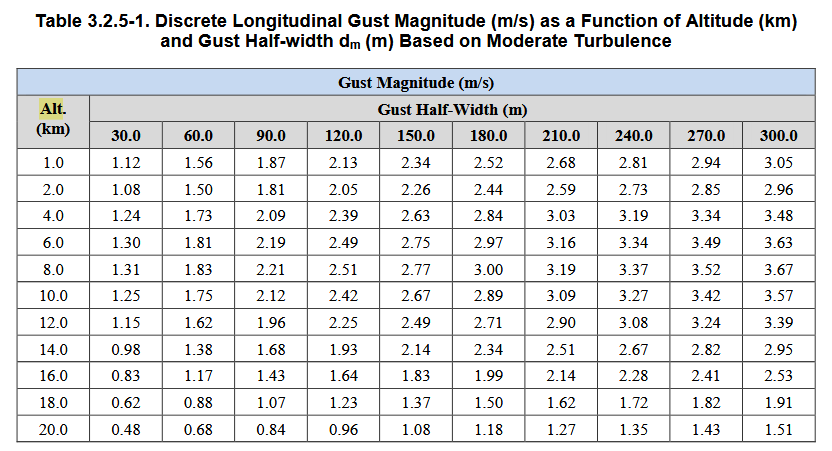

Choose a shorter gust half-width for a more conservative estimate - in this case, the smallest denomination is `30.0m `as shown in the table above. Also pick the 1 km gust maginitude, 1.12m/s

%user inputs
dmMQ = 30;
vm = 1.12

vm = 1.1200

Setting the range of values for the altitude(according to the decided `30.0m` half width, as well as distance into gust):

function [gust, gustArray] = buildGustFromAltRange(tU, altU, velU, altRange_m, N)
% buildGustFromAltRange
% Creates gust time/alt/distance-into-gust arrays using an altitude window.


=== Gust profile arrays created (from altitude range) ===
Alt range: 1038.818 to 1098.818 m
t range:   5.52055 to 5.70142 s
dist end:  59.9997 m


gust = struct with fields:
      t_start: 5.5206
        t_end: 5.7014
    alt_start: 1.0388e+03
      alt_end: 1.0988e+03
     distance: 59.9997


gustArray = 1.0e+03 *

    0.0055    1.0388         0         0
    0.0055    1.0391    0.0003    0.0000
    0.0055    1.0394    0.0006    0.0000
    0.0055    1.0397    0.0009    0.0000
    0.0055    1.0400    0.0012    0.0000
    0.0055    1.0403    0.0015    0.0000
    0.0055    1.0406    0.0018    0.0000
    0.0055    1.0409    0.0021    0.0000
    0.0055    1.0412    0.0024    0.0000
    0.0055    1.0415    0.0027    0.0000
    0.0055    1.0418    0.0030    0.0001
    0.0055    1.0421    0.0033    0.0001
    0.0055    1.0424    0.0036    0.0001
    0.0055    1.0427    0.0039    0.0001
    0.0055    1.0430    0.0042    0.0001


%
% Inputs
%   tU, altU, velU   : time (s), altitude (m), velocity (m/s); must be same length, sorted, unique in time
%   altRange_m       : [alt_start, alt_end] in meters (order doesn't matter)
%   N                : number of sample points in the gust window (default 200)
%
% Outputs
%   gust             : struct with t_start, t_end, alt_start, alt_end, distance
%   gustArray        : numeric array [time, altitude, dist_into_gust, frac]

    if nargin < 5 || isempty(N)
        N = 200;
    end
    if numel(altRange_m) ~= 2
        error("altRange_m must be a 2-element vector: [alt_start, alt_end] in meters.");
    end

    % --- ensure ascending alt range
    alt0 = min(altRange_m);
    alt1 = max(altRange_m);

    % --- quick checks
    if any(isnan(tU)) || any(isnan(altU)) || any(isnan(velU))
        error("Inputs contain NaNs. Clean your arrays first.");
    end

    % --- find times when altitude crosses alt0 and alt1
    % assumes altU is mostly monotonic in the segment you're targeting (ascent).
    % If your sim includes descent, we restrict to the first time it hits each altitude.
    t_start = interpTimeAtAlt(tU, altU, alt0);
    t_end   = interpTimeAtAlt(tU, altU, alt1);


     Time     Velocity
    ______    ________

    5.5206     331.49 
    5.5215     331.49 
    5.5224      331.5 
    5.5233      331.5 
    5.5242     331.51 
    5.5251     331.51 
     5.526     331.52 
    5.5269     331.52 
    5.5278     331.53 
    5.5287     331.53 
    5.5296     331.54 
    5.5306     331.54 
    5.5315     331.55 
    5.5324     331.55 
    5.5333     331.56 
    5.5342     331.56 
    5.5351     331.57 
     5.536     331.57 
    5.5369     331.58 
    5.5378     331.58 
    5.5387     331.59 
    5.5396     331.59 
    5.5405      331.6 
    5.5415      331.6 
    5.5424      331.6 
    5.5433     331.61 
    5.5442     331.61 
    5.5451     331.62 
     5.546     331.62 
    5.5469     331.63 
    5.5478     331.63 
    5.5487     331.64 
    5.5496     331.64 
    5.5505     331.65 
    5.5515     331.65 
    5.5524     331.66 
    5.5533     331.66 
    5.5542     331.67 
    5.5551 

    if isempty(t_start) || isempty(t_end)
        error("Could not find both altitude crossings within the provided data range.");
    end
    if t_end <= t_start
        error("Computed t_end <= t_start. Check that your altitude range is on the ascent portion.");
    end

    % --- sample times across the window
    tSamples = linspace(t_start, t_end, N).';

    % --- interpolate altitude & velocity at those times
    altSamples = interp1(tU, altU, tSamples, "linear", "extrap");
    velSamples = interp1(tU, velU, tSamples, "linear", "extrap");

    % --- distance into gust: cumulative integral of v dt from t_start
    distIntoGust = cumtrapz(tSamples, velSamples);
    gustDistance = distIntoGust(end);

    % --- fraction through gust
    if abs(gustDistance) > 0
        fracIntoGust = distIntoGust ./ gustDistance;

     Time     LateralAcceleration
    ______    ___________________

    5.5206          0.80879      
    5.5215          0.80106      
    5.5224          0.79334      
    5.5233          0.78561      
    5.5242          0.77789      
    5.5251          0.77016      
     5.526          0.76244      
    5.5269          0.75471      
    5.5278          0.74699      
    5.5287          0.73926      
    5.5296          0.73153      
    5.5306          0.72381      
    5.5315          0.71608      
    5.5324          0.70836      
    5.5333          0.70063      
    5.5342          0.69291      
    5.5351          0.68518      
     5.536          0.67746      
    5.5369          0.66973      
    5.5378          0.66201      
    5.5387          0.65428      
    5.5396          0.64655      
    5.5405          0.63883      
    5.5415           0.6311      
    5.5424          0.62338      
    5.5433   

    else
        fracIntoGust = zeros(size(distIntoGust));
    end

    % clamp
    fracIntoGust = max(0, min(1, fracIntoGust));
    distIntoGust = max(0, min(gustDistance, distIntoGust));

    % --- outputs
    gust = struct();
    gust.t_start   = t_start;
    gust.t_end     = t_end;
    gust.alt_start = alt0;
    gust.alt_end   = alt1;
    gust.distance  = gustDistance;

    gustProfile = struct();
    gustProfile.time           = tSamples;
    gustProfile.alt            = altSamples;
    gustProfile.dist_into_gust = distIntoGust;

     Time     AoA
    ______    ___

    5.5206    NaN
    5.5215    NaN
    5.5224    NaN
    5.5233    NaN
    5.5242    NaN
    5.5251    NaN
     5.526    NaN
    5.5269    NaN
    5.5278    NaN
    5.5287    NaN
    5.5296    NaN
    5.5306    NaN
    5.5315    NaN
    5.5324    NaN
    5.5333    NaN
    5.5342    NaN
    5.5351    NaN
     5.536    NaN
    5.5369    NaN
    5.5378    NaN
    5.5387    NaN
    5.5396    NaN
    5.5405    NaN
    5.5415    NaN
    5.5424    NaN
    5.5433    NaN
    5.5442    NaN
    5.5451    NaN
     5.546    NaN
    5.5469    NaN
    5.5478    NaN
    5.5487    NaN
    5.5496    NaN
    5.5505    NaN
    5.5515    NaN
    5.5524    NaN
    5.5533    NaN
    5.5542    NaN
    5.5551    NaN
     5.556    NaN
    5.5569    NaN
    5.5578    NaN
    5.5587    NaN
    5.5596    NaN
    5.5605    NaN
    5.5615    NaN
    5.5624    NaN
    5.5633    NaN
    5.5642    NaN
    5.5651   

    gustProfile.frac           = fracIntoGust;

    gustArray = [tSamples, altSamples, distIntoGust, fracIntoGust];

    % --- sanity prints
    fprintf("\n=== Gust profile arrays created (from altitude range) ===\n");
    fprintf("Alt range: %.3f to %.3f m\n", alt0, alt1);
    fprintf("t range:   %.6g to %.6g s\n", tSamples(1), tSamples(end));
    fprintf("dist end:  %.6g m\n", distIntoGust(end));
end


function t_cross = interpTimeAtAlt(tU, altU, altTarget)
% Returns first time altitude crosses altTarget (linear interpolation).
% If no crossing exists, returns [].

    % Find indices where sign changes or exact hit occurs
    a = altU - altTarget;

    % exact hit
    idxExact = find(a == 0, 1, "first");

     Time     WindVelocity
    ______    ____________

    5.5206       1.9362   
    5.5215       1.9378   
    5.5224       1.9395   
    5.5233       1.9411   
    5.5242       1.9427   
    5.5251       1.9444   
     5.526        1.946   
    5.5269       1.9476   
    5.5278       1.9493   
    5.5287       1.9509   
    5.5296       1.9526   
    5.5306       1.9542   
    5.5315       1.9558   
    5.5324       1.9575   
    5.5333       1.9591   
    5.5342       1.9607   
    5.5351       1.9624   
     5.536        1.964   
    5.5369       1.9656   
    5.5378       1.9673   
    5.5387       1.9689   
    5.5396       1.9706   
    5.5405       1.9722   
    5.5415       1.9738   
    5.5424       1.9755   
    5.5433       1.9771   
    5.5442       1.9787   
    5.5451       1.9804   
     5.546        1.982   
    5.5469       1.9836   
    5.5478       1.9853   
    5.5487       1.9869   
    5.5496   

    if ~isempty(idxExact)
        t_cross = tU(idxExact);
        return;
    end

    % sign change across adjacent samples
    idx = find(a(1:end-1) .* a(2:end) < 0, 1, "first");
    if isempty(idx)
        t_cross = [];
        return;
    end

    % linear interpolation between idx and idx+1
    t1 = tU(idx);    t2 = tU(idx+1);
    a1 = a(idx);     a2 = a(idx+1);

    % a(t) linear -> solve for a=0
    t_cross = t1 + (t2 - t1) * (-a1) / (a2 - a1);
end


Now needing the vel

Using the code above but for the distances of max Q and such:

altRange_m = [maxQ.alt - dmMQ, maxQ.alt + dmMQ];
N = 200;
[gust, gustArray] = buildGustFromAltRange(tU, altU, velU, altRange_m, N)
% buildGustFromAltRange
% Creates gust time/alt/distance-into-gust arrays using an altitude window.
%
% Inputs
%   tU, altU, velU   : time (s), altitude (m), velocity (m/s); must be same length, sorted, unique in time
%   altRange_m       : [alt_start, alt_end] in meters (order doesn't matter)
%   N                : number of sample points in the gust window (default 200)
%
% Outputs
%   gust             : struct with t_start, t_end, alt_start, alt_end, distance
%   gustProfile      : struct with .time, .alt, .dist_into_gust, .frac
%   gustArray        : numeric array [time, altitude, dist_into_gust, frac]

Now, I need the velocity of the vehicle in the gust:

%% Gust time bounds (already known)
t1 = gust.t_start;
t2 = gust.t_end;

%% Generate 200 evenly spaced time samples inside gust
t_query = linspace(t1, t2, 200);

%% Ensure time vector is monotonic + unique
[t_u, iu] = unique(t, "stable");
vel_u = vel(iu);

%% Interpolate velocity at gust times

Gust magnitude at alt = 1.11468 km, d_m = 30.0 m: 2.6718 m/s


vel_query = interp1(t_u, vel_u, t_query, "linear", "extrap");

%% Store results
vehicleVelTimeGustCOS = table(t_query(:), vel_query(:), ...
    'VariableNames', ["Time","Velocity"]);

disp(vehicleVelTimeGustCOS)


As well as the lateral acceleration:

%% Gust time bounds
t1 = gust.t_start;
t2 = gust.t_end;

%% Generate 200 evenly spaced time samples inside gust
t_query = linspace(t1, t2, 200);

%% Ensure time vector is monotonic + unique
[t_u, iu] = unique(t, "stable");
acc_u = acc(iu);   % lateral accel aligned with time

%% Interpolate lateral acceleration at gust times
acc_query = interp1(t_u, acc_u, t_query, "linear", "extrap");

%% Store results
vehicleLAccTimeGustCOS = table(t_query(:), acc_query(:), ...
    'VariableNames', ["Time","LateralAcceleration"]);

disp(vehicleLAccTimeGustCOS)

As well as the AoA:

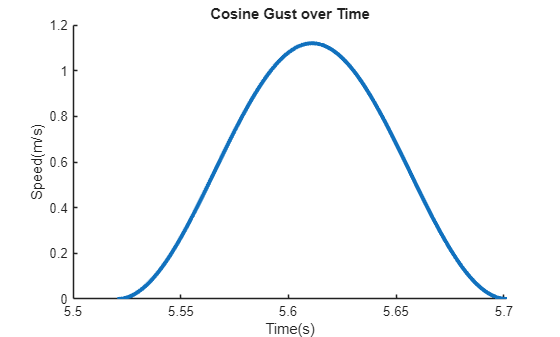

%% Gust time bounds
t1 = gust.t_start;
t2 = gust.t_end;

%% Generate 200 evenly spaced time samples inside gust
t_query = linspace(t1, t2, 200);


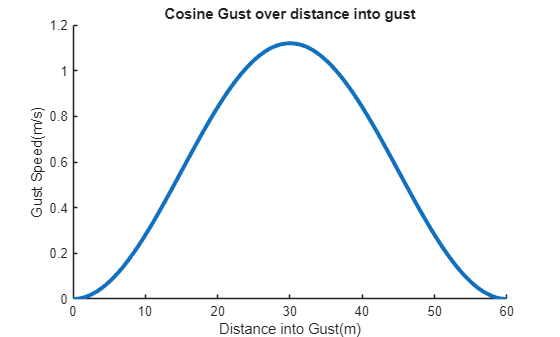

%% Ensure time vector is monotonic + unique
[t_u, iu] = unique(t, "stable");
aoa_u = aoa(iu);

%% Interpolate AoA at gust times
aoa_query = interp1(t_u, aoa_u, t_query, "linear", "extrap");


%% Store results
vehicleAoATimeGustCOS = table(t_query(:), aoa_query(:), ...
    'VariableNames', ["Time","AoA"]);

disp(vehicleAoATimeGustCOS)


As well as the wind and gust velocity:

%% Gust time bounds
t1 = gust.t_start;

dBodyTube = 0.1690

t2 = gust.t_end;

%% Generate 200 evenly spaced time samples inside gust
t_query = linspace(t1, t2, 200);

%% Ensure time vector is monotonic + unique
[t_u, iu] = unique(t, "stable");
wind_u = wind(iu);

%% Interpolate wind velocity at gust times
wind_query = interp1(t_u, wind_u, t_query, "linear", "extrap");

finGammaC = 1.0297


%% Store results
vehicleWindTimeGustCOS = table(t_query(:), wind_query(:), ...
    'VariableNames', ["Time","WindVelocity"]);

disp(vehicleWindTimeGustCOS)



Since there is no explicit gust value between 1.0km and 2.0 km, interpolate the values from the `Table 3.2.5-3. Discrete Longitudinal Gust Magnitude (m/s) as a Function of Altitude (km)`

`and Gust Half-width dm (m) Based on Severe Turbulence`

%% Discrete Longitudinal Gust Magnitude Table (SEVERE Turbulence)
% Table 3.2.5-3: Discrete Longitudinal Gust Magnitude (m/s) vs Altitude (km)
% and Gust Half-Width d_m (m)

% Altitude grid (km)
alt_km = [ ...

ans = 1.0688e+03

     1

v_WindVehicleMaxQ = 58.0384

     2
     4
     6
     8
    10
    12
    14
    16
    18
    20
    25
    30
    35

Ma_4CNA = 0.0024

    40
    45
    50
    55
    60
    65
    70

beta = 0.2431

    75
    80 ];

% Gust half-width grid d_m (m)
dm_m = [30 60 90 120 150 180 210 240 270 300];

% Gust magnitude (m/s): rows = alt_km, cols = dm_m
G = [ ...
    2.65 3.68 4.43 5.03 5.53 5.95 6.32 6.65 6.94 7.20;  %  1 km
    2.84 3.95 4.77 5.42 5.96 6.43 6.84 7.20 7.52 7.81;  %  2 km
    3.81 5.31 6.41 7.30 8.05 8.69 9.26 9.77 10.23 10.64; %  4 km
    4.37 6.09 7.35 8.37 9.23 9.98 10.63 11.21 11.74 12.21; %  6 km
    4.63 6.45 7.79 8.88 9.79 10.58 11.27 11.89 12.44 12.94; %  8 km
    4.34 6.06 7.34 8.37 9.25 10.02 10.70 11.30 11.85 12.36; % 10 km
    3.68 5.16 6.27 7.18 7.96 8.65 9.27 9.83 10.35 10.82; % 12 km
    2.59 3.64 4.44 5.10 5.67 6.18 6.64 7.06 7.45 7.81;  % 14 km
    1.70 2.40 2.92 3.36 3.74 4.08 4.39 4.67 4.94 5.18;  % 16 km
    1.14 1.61 1.97 2.27 2.53 2.76 2.98 3.17 3.35 3.53;  % 18 km
    0.82 1.16 1.42 1.64 1.83 2.00 2.16 2.31 2.44 2.57;  % 20 km
    0.79 1.12 1.36 1.57 1.76 1.92 2.07 2.21 2.35 2.47;  % 25 km

sfins = 0.1500

    0.66 0.93 1.14 1.32 1.47 1.61 1.74 1.86 1.97 2.08;  % 30 km
    0.73 1.03 1.26 1.46 1.63 1.79 1.93 2.06 2.18 2.30;  % 35 km
    0.76 1.08 1.32 1.52 1.70 1.86 2.01 2.15 2.28 2.40;  % 40 km

AR = 0.0063

    0.83 1.18 1.44 1.66 1.86 2.03 2.20 2.35 2.49 2.62;  % 45 km
    0.90 1.28 1.56 1.81 2.02 2.21 2.39 2.55 2.71 2.85;  % 50 km
    1.01 1.43 1.76 2.03 2.27 2.48 2.68 2.86 3.04 3.20;  % 55 km
    1.10 1.56 1.91 2.21 2.47 2.70 2.92 3.12 3.31 3.49;  % 60 km
    1.17 1.65 2.02 2.34 2.61 2.86 3.09 3.30 3.50 3.69;  % 65 km
    1.56 2.21 2.71 3.12 3.49 3.82 4.13 4.42 4.68 4.93;  % 70 km
    1.79 2.53 3.10 3.58 4.01 4.39 4.74 5.07 5.37 5.66;  % 75 km
    2.02 2.86 3.50 4.05 4.52 4.95 5.35 5.72 6.07 6.39   % 80 km
];


finBodR = 1.8723

finRatInD = 0.0030

fin1_Cna = 0.0185

%% Build interpolant once
% 'linear' interpolation, 'nearest' extrap outside grid (safer than guessing)
F = griddedInterpolant({alt_km, dm_m}, G, "linear", "nearest");

%% ---- YOU ONLY CHANGE THESE LINES ----
alt_query_km = 1.11468;  % your altitude in km
dm_query_m   = 30;       % gust half-width (m)
% --------------------------------------

gust_mag_ms = F(alt_query_km, dm_query_m);

fprintf("Gust magnitude at alt = %.5f km, d_m = %.1f m: %.4f m/s\n", ...
    alt_query_km, dm_query_m, gust_mag_ms);



From above:

`=== Gust profile arrays created (from altitude range) ===`

`Alt range: 1032.074 to 1092.074 m`

Using the code above


$$V_g(x)=\frac{V_{m}}{2}(1-cos(\frac{\pi d}{d_m})) \ \ \ \ for \ 0 \leq x \leq 2d_m$$


$V_m(d)$ - gust magnitude  (ft/s or m/s)

$V_{m}$ - design gust velocity (set by altitude & category)

$d$ - Distance flown into the gust

$d_m$ - Gust gradient length (half-length of gust)

% Distance into gust
s = gustArray(:,3);

sfins = 0.1500


% Gust length so peak occurs at launchRailH
dmMQ;

Lgust = gust.distance;          % NOT (gust.alt_end - gust.alt_start)

rtfins = 0.0840

inside = (s >= 0) & (s <= Lgust);
vg = zeros(size(s));

tauFins = 2.7857



vg(inside) = (vm/2) .* (1 - cos(pi * s(inside) / dmMQ));

vm = gust_mag_ms;

% vg(inside) = (vm/2) .* (1 - cos(pi * s(inside) / dmMQ));
% equivalently: (vm/2)*(1 - cos(2*pi*s/Lgust))

% 

`Alt range: 1032.074 to 1092.074 m`


% Outside gust region vg remains zero
figure;

boattailCna = 0

hold on;
title('Cosine Gust over Time')
xlabel('Time(s)')
ylabel('Speed(m/s)')
plot(gustArray(:,1), vg, 'LineWidth', 3);

figure;
hold on;
title('Cosine Gust over distance into gust')
xlabel('Distance into Gust(m)')
ylabel('Gust Speed(m/s)')
plot(gustArray(:,3), vg, 'LineWidth', 3);
figure;



rCone = 0.0845

## Requirements for Estimating CnA for Fins

Note these are the assumptions made by Barrowman:

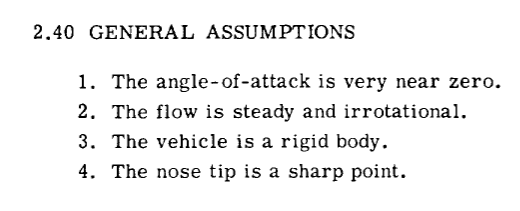

From Barrowman's The Practical Calculation of the Aerodynamic Characteristics of Slender Finned Vehicles(1967)

[https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf](https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf)


$$C_{n _\alpha} = \frac{2 \pi (A_f / A_r)} {2+ \sqrt{4 + (\frac{ \beta AR}{cos\Gamma_c }) \\
$$


For $\beta$ in the equation, for $C_{n _\alpha$

**Easily found values for Cna Calculation**

Ar = reference area of rocket body (based off body tube diameter)

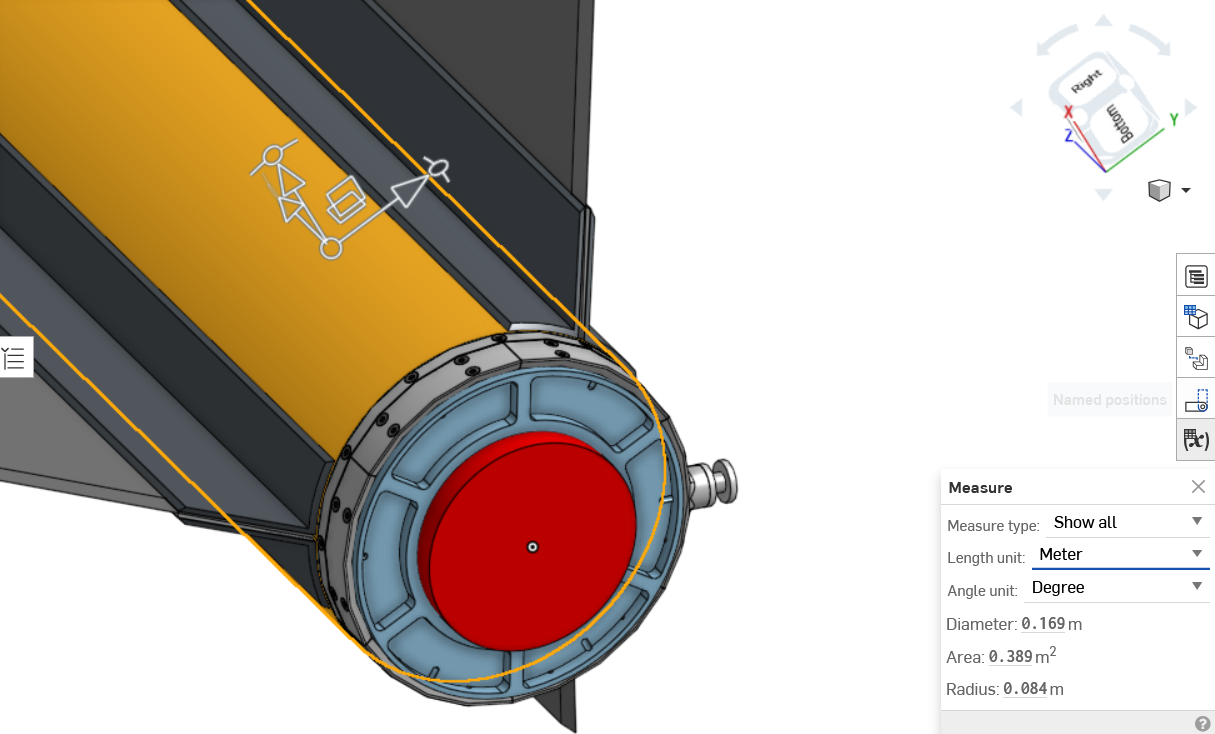

From the figure above:

dBodyTube = 0.169

Abn = 0.0224

bodyTubeArea = (pi*dBodyTube^2)/4;

Af = area of fins

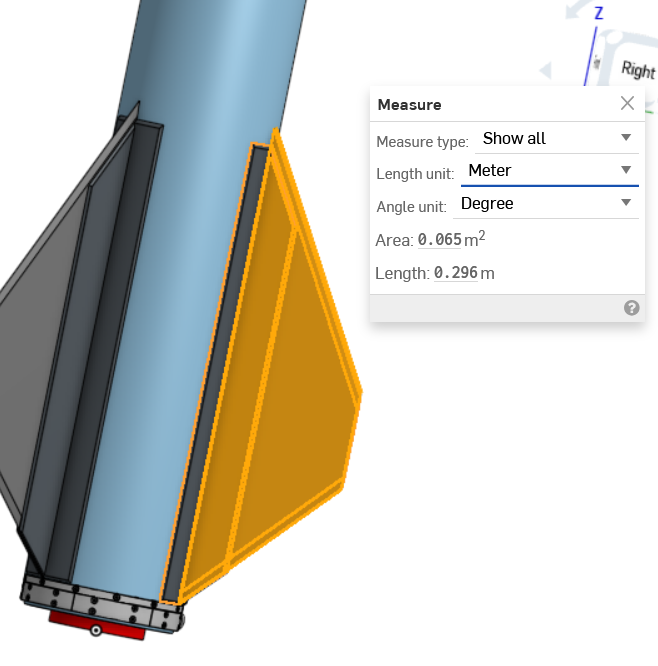

For Af:

From the figure above:

finA = 0.042;

noseCna = 2

**GAMMA_c - Midchord Line Sweep Angle**

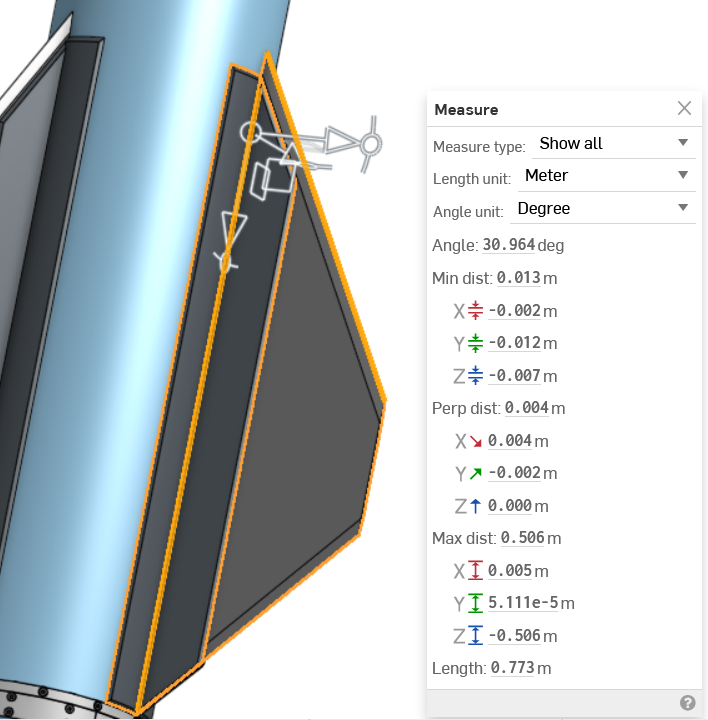

The midchord line sweep angle is measured above, at 30.964 degrees.

finGammaC = deg2rad(59)

For beta:

[https://en.wikipedia.org/wiki/Prandtl%E2%80%93Glauert_transformation?](https://en.wikipedia.org/wiki/Prandtl%E2%80%93Glauert_transformation?)

From above. $\beta = \sqrt{1-M_{\infty}^2 \\

M_{\infty} = freestream \ mach \ number$

## Calculating Beta for Fins CnA

[https://en.wikipedia.org/wiki/Freestream?](https://en.wikipedia.org/wiki/Freestream?utm_source=chatgpt.com)

For simplicity(and speed), only calculating the mach number for the velocity at max Q. Which is:


$$M_{\infty} = \frac{V_{\infty}}{c_{\infty}}  \\
V_\infty = V_{vehicle}-V_{air} \\$$


Extrapolating  the wind data from the RAWS to get max wind speed at the altitude of max Q:

Assuming the shear exponent(alpha) is equal to 0.2 . 


$$V_m = {V_{ref}*({\frac{z}{z_{ref}})^\alpha\\
V_m = 22.8*({\frac{8.4}{10})^{0.2}\\$$


maxQ.alt
v_WindVehicleMaxQ = 22.8*(maxQ.alt/10)^.2

To estimate Cna, get the Speed of Sound from the "Tables of the U.S Standard Atmosphere"(1976) at max Q

[https://www.digitaldutch.com/atmoscalc/](https://www.digitaldutch.com/atmoscalc/)

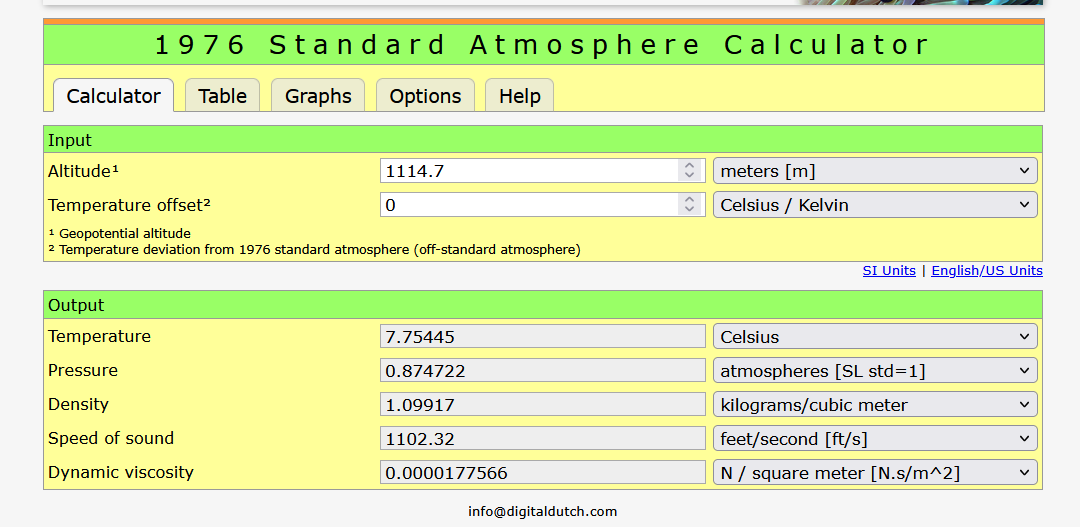

cforCNA = 1102.32;

cforCNA = 320.55 m/s at z = 5km.

Note that from previous discrete gust modeling, V = 

v_air = (v_WindVehicleMaxQ + max(vm));

And then for $V_{\inf}$  :

v_inf4CNA = abs((v_WindVehicleMaxQ - v_air));

% Note that, I origainlly did v_inf = v_air - V_WindVehicle

Now that we have v_air and c, can calc freestream mach number:

Ma_4CNA = v_inf4CNA/cforCNA
% Ma_4CNA = machSeg


Instead of the above, due to Peter's feedback on 2/18/26

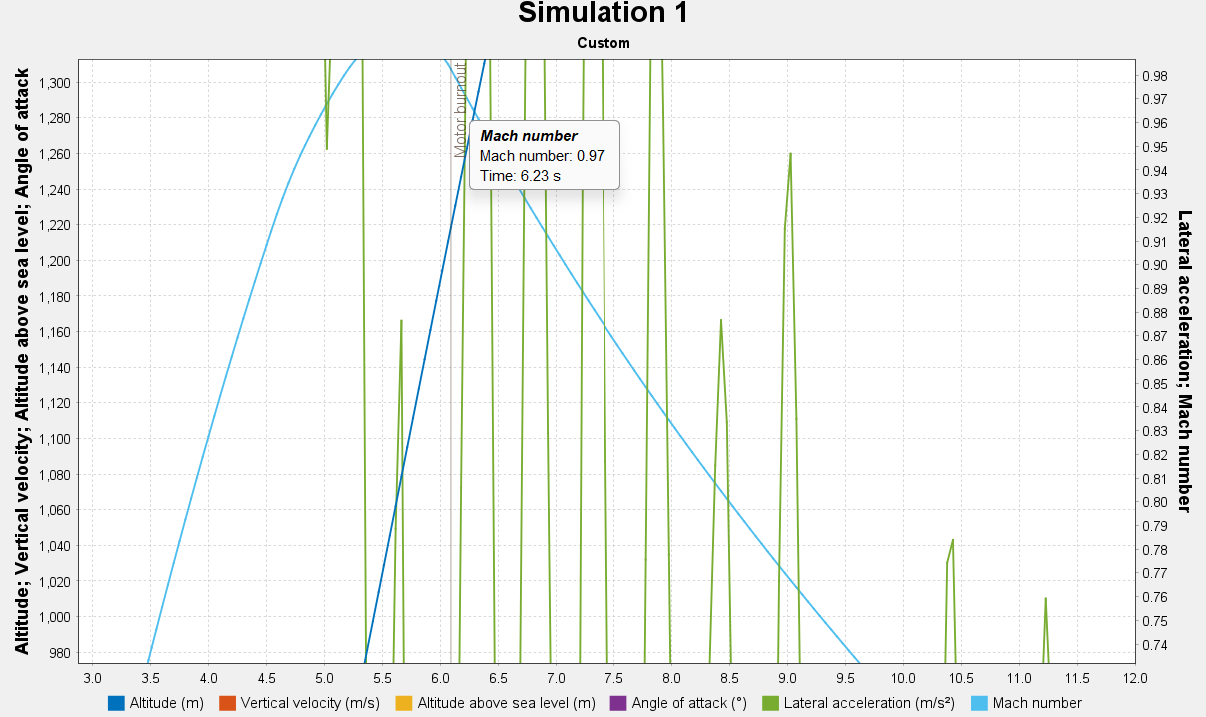

Recall:


$$\beta = \sqrt{1-M_{\infty}^2 \\

M_{\infty} = freestream \ mach \ number$$


beta = sqrt(1-.97^2)


## Calculating Aspect Ratio for Fins

From:

[https://en.wikipedia.org/wiki/Aspect_ratio_(aeronautics)](https://en.wikipedia.org/wiki/Aspect_ratio_(aeronautics))

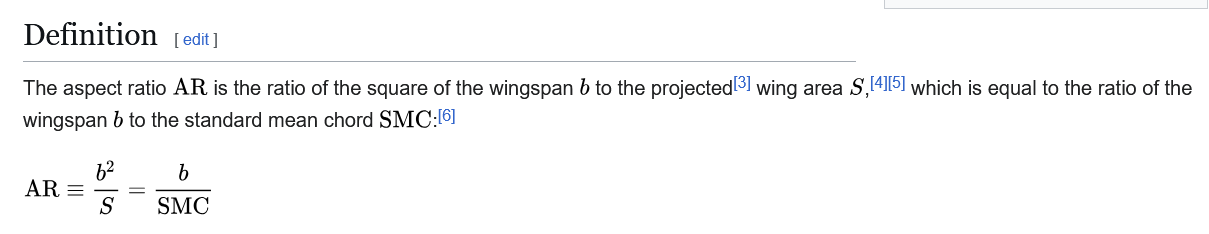

Note that Root Chord from this equation is 

Source that helps understand how to calculate the effective aspect ratio

[https://www.rocketmime.com/rockets/Barrowman.html?](https://www.rocketmime.com/rockets/Barrowman.html?)

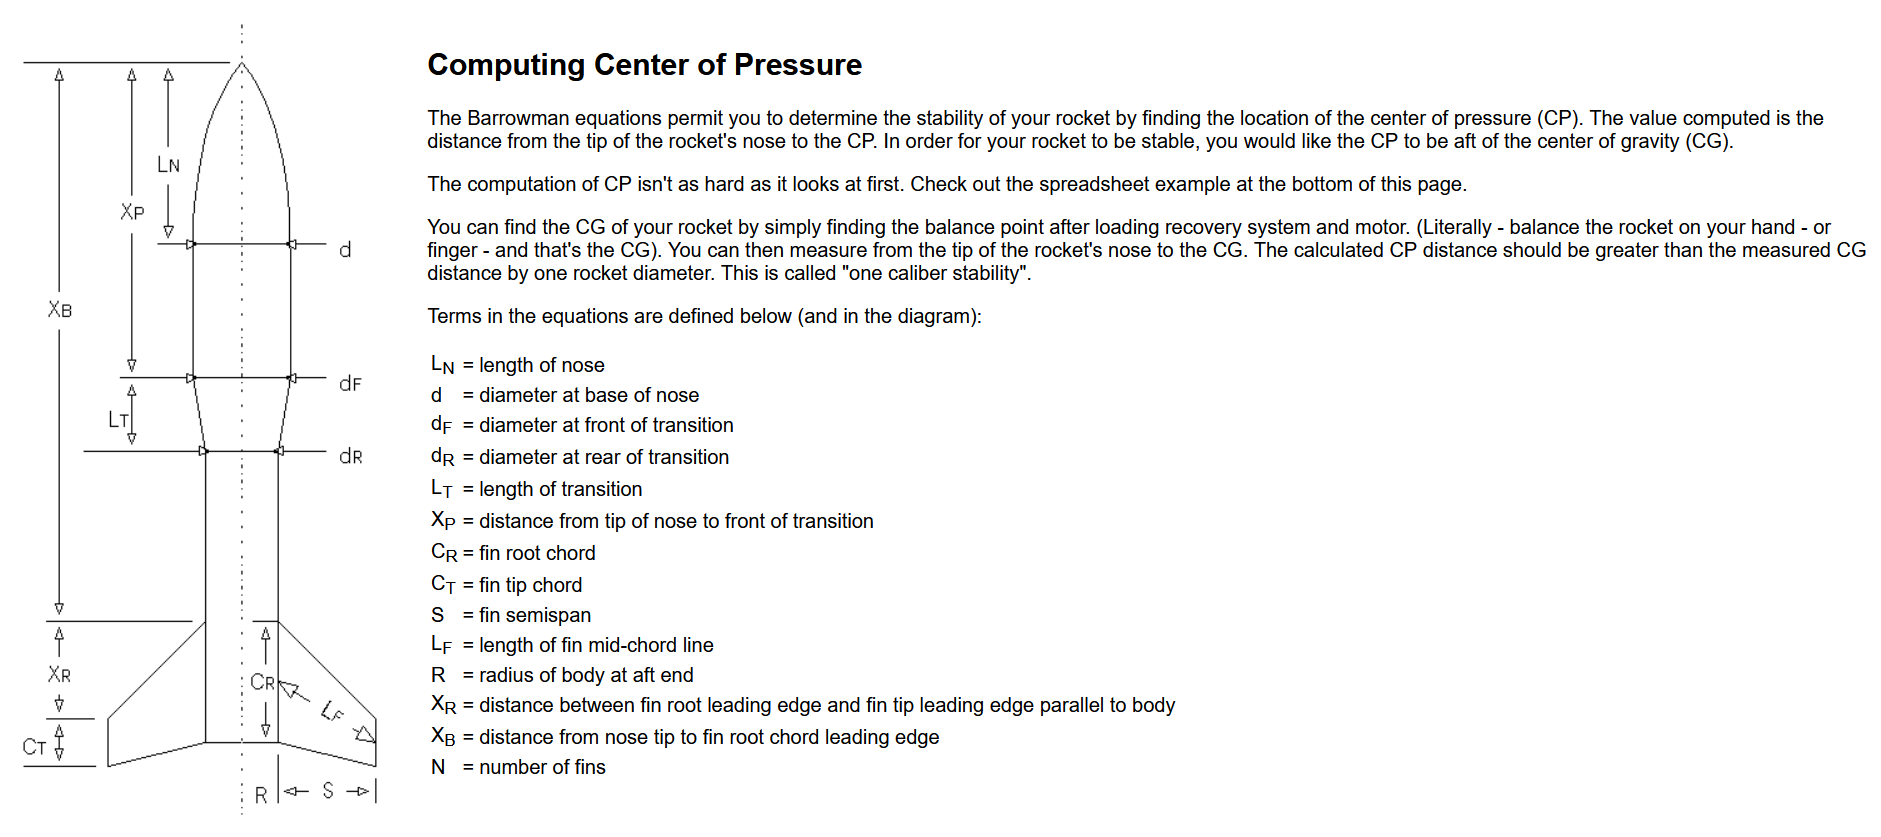

 OnShape: "LV3.1 Full Assembly": pulled from "Main" Branch 2/12/26:

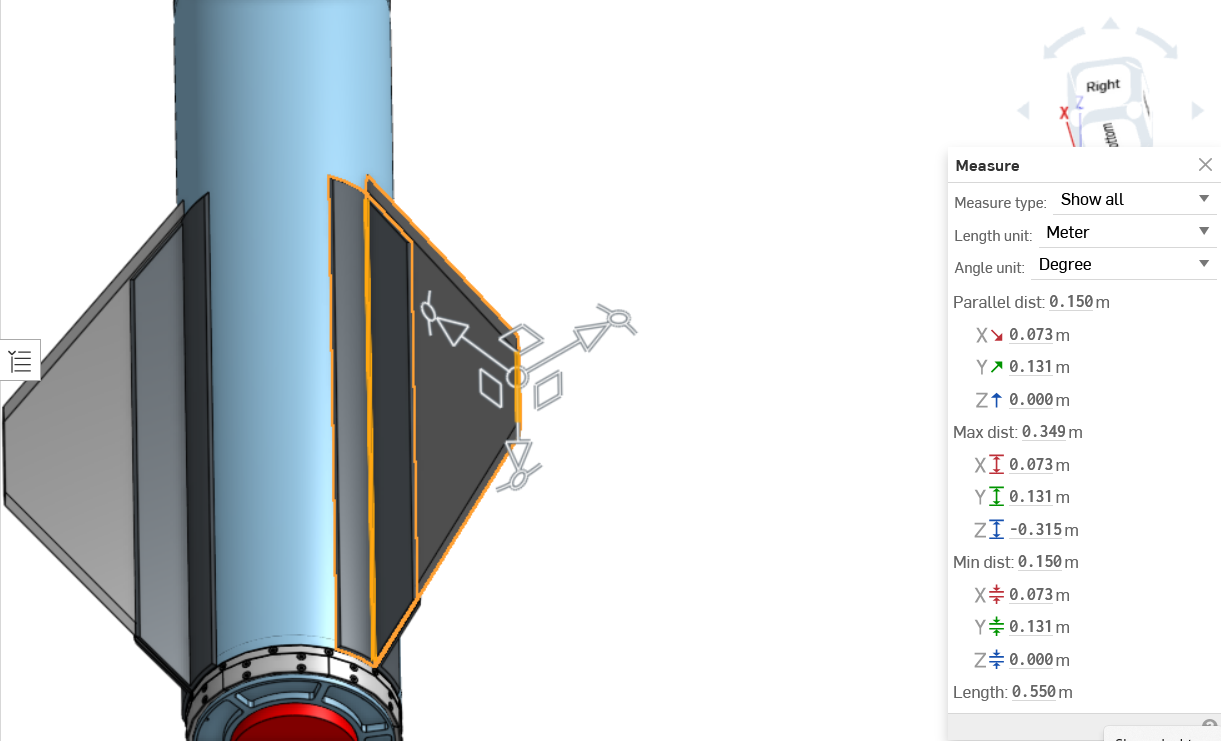

For span of the fin:

From the figure above:

sfins = 0.150 % in meters

% Now that we have all of the fin data we wanted
AR = sfins*finA


## Estimating Cna for fins

From Barrowman's The Practical Calculation of the Aerodynamic Characteristics of Slender Finned Vehicles(1967).

[https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf](https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf)

This particular equation uses a beta at ONLY the altitude of the Q, so this may cause the beta to be a more conservative value, and thus the Cna is a more conservative value.

For a singular fin:


$$C_{n _\alpha} = \frac{2 \pi (A_f / A_r)AR} {2+ \sqrt{4 + (\frac{ \beta AR}{cos\Gamma_c }) \\
$$


finBodR = finA/bodyTubeArea
finRatInD = (beta*AR)/(cos(finGammaC))
fin1_Cna = (2*pi * finBodR*AR)/ (2 + sqrt(4 + finRatInD))


In order for the total Cna to equal the summation of fin Cna, the angle of attack must be sufficiently small (< 10 degrees). These conditions were verified by looking at the OpenRocket graph below:

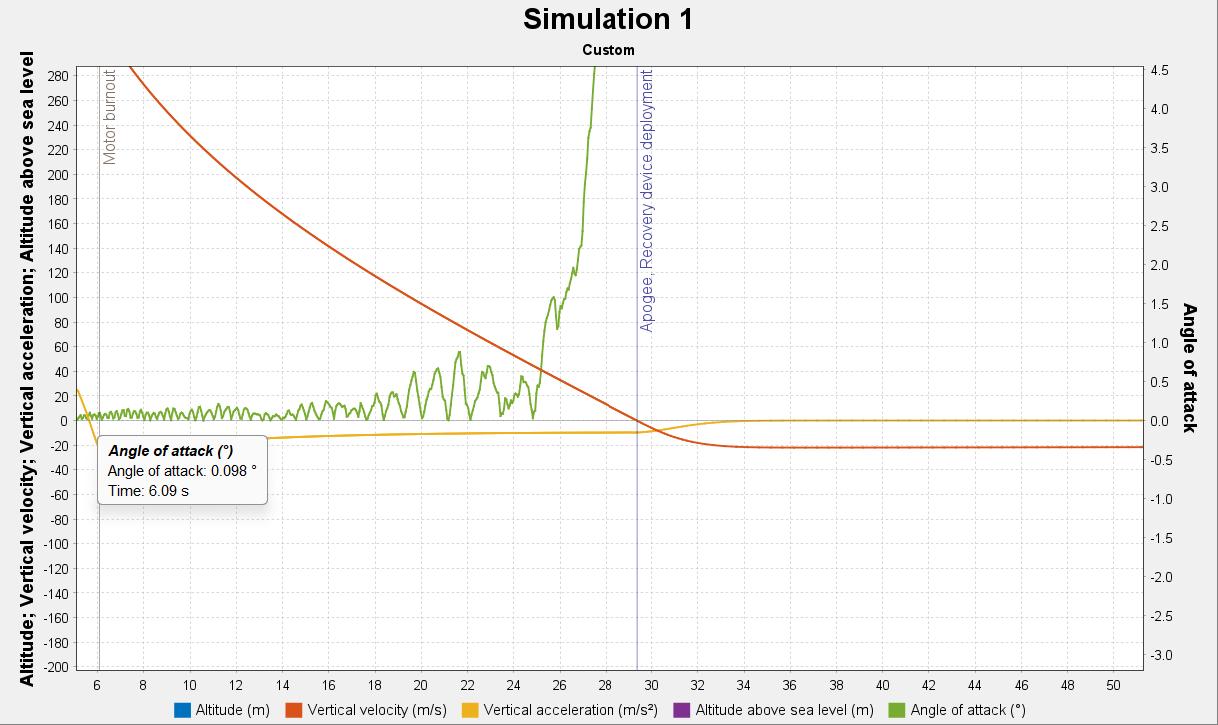

finsCna = fin1_Cna + fin1_Cna + fin1_Cna;

[](https://en.wikipedia.org/wiki/Freestream?utm_source=chatgpt.com)

## Calculating Boat Tail Ratio(Placeholder)

From Barrowman's The Practical Calculation of the Aerodynamic Characteristics of Slender Finned Vehicles(1967)

[https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf](https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf)

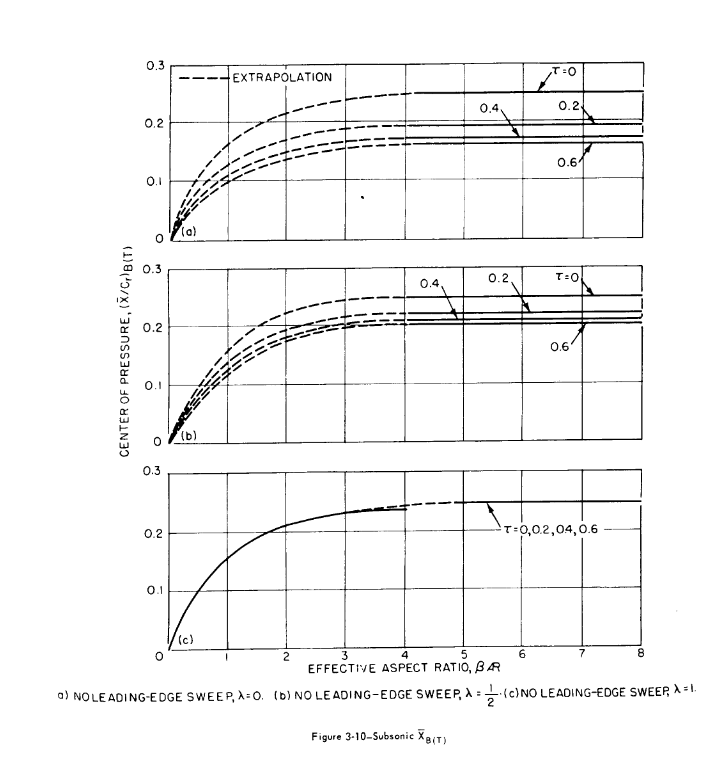

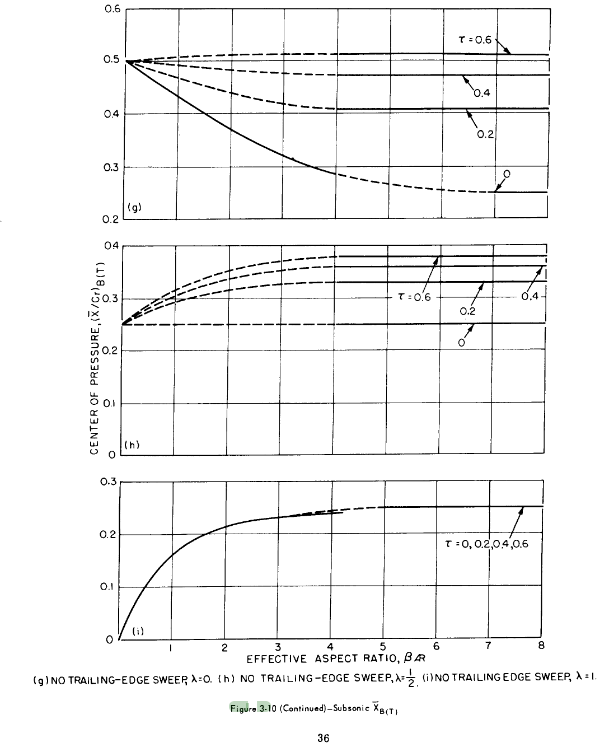

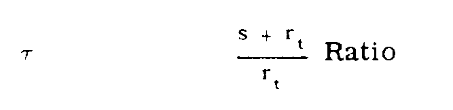

Note that Root Chord from this equation is 

Source that helps understand how to calculate the effective aspect ratio

[https://www.rocketmime.com/rockets/Barrowman.html?](https://www.rocketmime.com/rockets/Barrowman.html?)

 OnShape: "LV3.1 Full Assembly": pulled from "Main" Branch 2/12/26:

From the figure above:

sfins = 0.150 % in meters

Since larger tau correlates with smaller $r_t$, for radius we used the radius of the body tube, rather than at the fin chord.

From the figure above:

rtfins = 0.084 % in meters

With the rtfins and sfins from the CAD model, can now calculate $\tau
$ :

tauFins = (sfins + rtfins)/rtfins


## Estimating Cna for Boat Tail

**Temporarily, since we do not use a boat tail, pick Cna =0**

Note that this section is incomplete. That is because the fincan group has not yet completed their choice of boattail yet. This is a placeholder

From Barrowman's The Practical Calculation of the Aerodynamic Characteristics of Slender Finned Vehicles(1967)

[https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf](https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf)

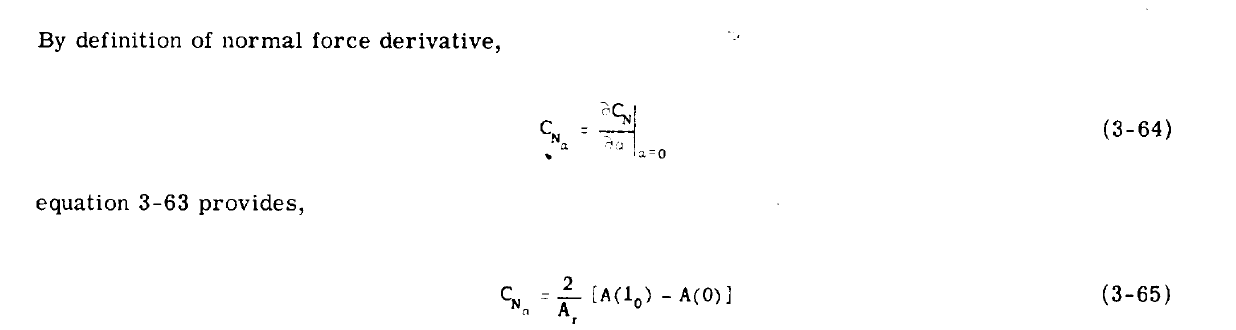

where Ar (reference area is  = 

Skinny of boat tail is A(l_0)

Fat end of boat tail is A(l_0)

Ar = area of the rocket body tube

boattailCna = 0



## Nose Cone: Normal Force Coefficient

From Barrowman's The Practical Calculation of the Aerodynamic Characteristics of Slender Finned Vehicles(1967). Page 21 - 22.

[https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf](https://ntrs.nasa.gov/api/citations/20010047838/downloads/20010047838.pdf)

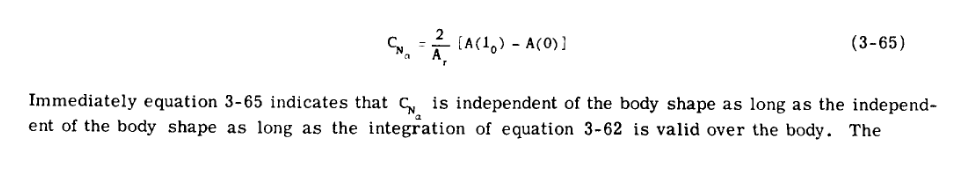

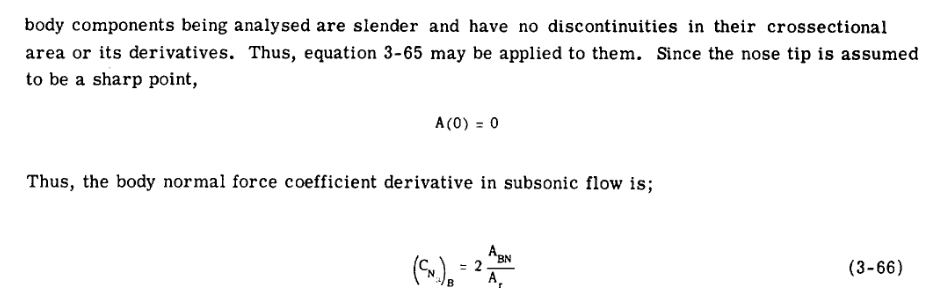

From the quotation of Barrowman above, the analysis for the CnA of a cone is the same as the body of the rocket(with the area changes being captured in the A(l0) - A(0).

Where $A_{BN}$ = body-nosecone interface area

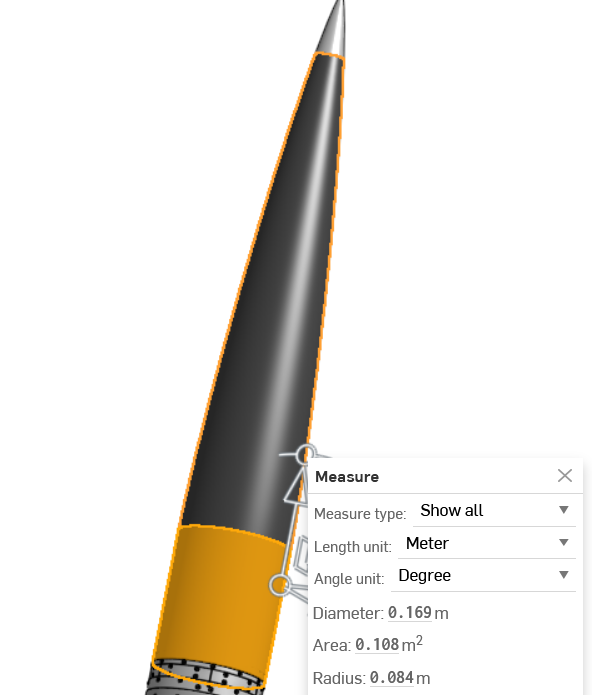

Then, from the figure above, calculate $A_{BN}$.

rCone = 0.169/2
Abn = pi*(rCone)^2

Now that we have $A_{BN}$ , we can calculate the normal force coefficient of the nose cone.

noseCna = 2 * (Abn/bodyTubeArea)

## Turning Gust Velocity into Shear Force

[http://www.aspirespace.org.uk/downloads/Rocket%20vehicle%20loads%20and%20airframe%20design.pdf](http://www.aspirespace.org.uk/downloads/Rocket%20vehicle%20loads%20and%20airframe%20design.pdf)

From Aspire Space Paper:


$$V_s(@x_k) = L_{nose}+L_{fins}-L_{boat-tail}-a_y \sum_{i=1}^{x_k}m-R\sum_{i=1}^{x_k}m(x_{cg}-x_m)$$


$d $ = fuselage diameter d

$R$ = Static Margin


$$R = \frac{9}{2I} \rho V d$$


For the L values:

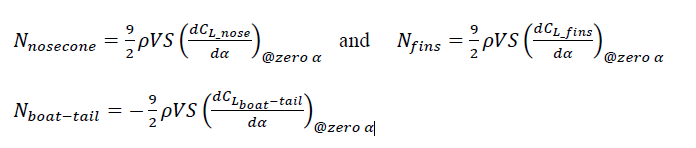

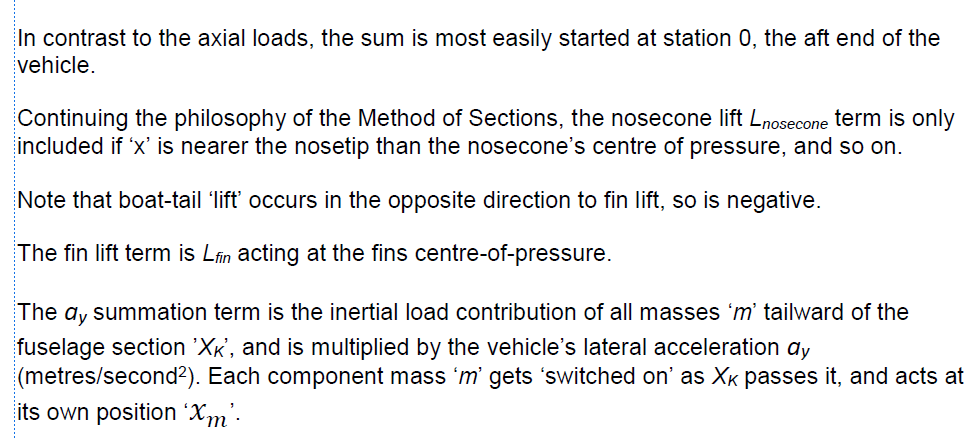

## Extracting the Mass Data

% --- OpenRocket CSV extraction: Mass + CG (distance from nose) ---
fn = "rocketComponentValuesOR.csv";

% Keep headers exactly as they appear in the CSV
T = readtable(fn, "TextType","string", "VariableNamingRule","preserve");

Using columns:


vars = string(T.Properties.VariableNames);

  Name: Component


  Mass: Instance Mass (g)


% ---- pick component/name column ----

  Xcg : Aggregate CG Location (cm)


if any(vars == "Component")

                   Component                   Mass_kg     Xcg_m_from_nose
    _______________________________________    ________    _______________

    "Nose cone"                                  4.3377        0.82899    
    "Drogue Can"                                0.51767         0.8904    
    "Shock Cord"                                0.54431        0.74415    
    "Metal Nose Cone Tip"                          0.24       0.049212    
    "threaded rod"                                0.163        0.09652    
    "drogue Parachute"                          0.18826          0.889    
    "arc clamp system"                         0.097567         2.1319    
    "ERS Micromodule Attached to Nose Cone"      2.0484          1.096    
    "arc clamp system"                         0.097567         2.2521    
    "Main Can Isogrid Module"                    6.4768         1.3307  

    nameCol = "Component";
elseif any(vars == "Name")
    nameCol = "Name";
else
    disp("Available columns:");
    disp(vars');
    error("No Component/Name column found.");
end
names = string(T.(nameCol));

% ---- pick mass column (prefer Instance) ----
if any(vars == "Instance Mass (g)")
    massCol = "Instance Mass (g)";
    wantPrefix = "instance";
elseif any(vars == "Aggregate Mass (g)")
    massCol = "Aggregate Mass (g)";
    wantPrefix = "aggregate";
else
    disp("Available columns:");
    disp(vars');
    error("No Mass column found (Instance Mass (g) or Aggregate Mass (g)).");
end

% ---- pick CG-location column (the header varies between OR exports) ----
vlow = lower(vars);

% First try: match same prefix + contains "cg" and "loc" and "(cm)"
cgIdx = contains(vlow, wantPrefix) & contains(vlow, "cg") & contains(vlow, "loc") & contains(vlow, "(cm)");

% If not found, loosen: any column containing "cg" and "loc" and "(cm)"
if ~any(cgIdx)
    cgIdx = contains(vlow, "cg") & contains(vlow, "loc") & contains(vlow, "(cm)");
end

% If still not found, loosen more: any column containing "cg" and "cm"
if ~any(cgIdx)
    cgIdx = contains(vlow, "cg") & contains(vlow, "cm");
end

if ~any(cgIdx)
    disp("Available columns:");
    disp(vars');
    error("No CG-location column found. Look for something like '... CG ... (cm)'.");
end

cgCol = vars(find(cgIdx,1,"first"));  % take first match

% ---- extract + convert units ----
m_kg    = T.(massCol) / 1000;     % g -> kg
xcg_m   = T.(cgCol)   / 100;      % cm -> m (OpenRocket axial position, typically from nose tip)

% ---- clean rows ----
valid = ~isnan(m_kg) & ~isnan(xcg_m) & (m_kg > 0);
names = names(valid);
m_kg  = m_kg(valid);
xcg_m = xcg_m(valid);

% Drop any "Total" row (avoid double count)
isTotal = contains(lower(names), "total");
names(isTotal) = [];
m_kg(isTotal)  = [];
xcg_m(isTotal) = [];

% ---- output a clean table + save ----
Tout = table(names, m_kg, xcg_m, 'VariableNames', {'Component','Mass_kg','Xcg_m_from_nose'});
disp("Using columns:");
disp("  Name: " + nameCol);
disp("  Mass: " + massCol);
disp("  Xcg : " + cgCol);
disp(Tout(1:min(15,height(Tout)),:));

writetable(Tout, "OR_mass_xcg_clean.csv");



Now needs to calculate for specfically the arc clamp in the back

% --- OpenRocket CSV extraction + cumulative sums about a chosen component station ---
fn = "rocketComponentValuesOR.csv";

% Keep headers exactly as they appear in the CSV
T = readtable(fn, "TextType","string", "VariableNamingRule","preserve");
vars = string(T.Properties.VariableNames);
vlow = lower(vars);

% ---- pick component/name column ----
if any(vars == "Component")
    nameCol = "Component";
elseif any(vars == "Name")
    nameCol = "Name";
else
    disp("Available columns:");

Using columns:
  Name: Component
  Mass: Instance Mass (g)
  Xcg : Aggregate CG Location (cm)


    disp(vars');

Selected component (rear-most match): arc clamp system


    error("No Component/Name column found.");

x_m (distance from nose) = 3.788330 m


end

Cumulative mass Σm = 46.022962 kg


names = string(T.(nameCol));

Cumulative first moment about nose Σ(m*x) = 102.960371 kg*m


Cumulative sum Σ m*(x_cg - x_m) = -71.389788 kg*m


% ---- pick mass column (prefer Instance) ----
if any(vars == "Instance Mass (g)")
    massCol = "Instance Mass (g)";
    wantPrefix = "instance";
elseif any(vars == "Aggregate Mass (g)")
    massCol = "Aggregate Mass (g)";
    wantPrefix = "aggregate";
else
    disp("Available columns:");
    disp(vars');
    error("No Mass column found (Instance Mass (g) or Aggregate Mass (g)).");
end

% ---- pick CG-location column (distance from nose, in cm) ----
cgIdx = contains(vlow, wantPrefix) & contains(vlow,"cg") & contains(vlow,"loc") & contains(vlow,"(cm)");
if ~any(cgIdx)
    cgIdx = contains(vlow,"cg") & contains(vlow,"loc") & contains(vlow,"(cm)");
end
if ~any(cgIdx)
    cgIdx = contains(vlow,"cg") & contains(vlow,"cm");
end
if ~any(cgIdx)
    disp("Available columns:");
    disp(vars');
    error("No CG Location column found (look for something like '...CG...Location...(cm)').");
end
cgCol = vars(find(cgIdx,1,"first"));

% ---- extract + convert units (OpenRocket axial CG is typically from nose tip) ----
m = T.(massCol)/1000;      % g -> kg
x = T.(cgCol)/100;         % cm -> m from nose tip

% ---- clean rows ----
valid = ~isnan(m) & ~isnan(x) & (m > 0);
m = m(valid); x = x(valid); names = names(valid);

isTotal = contains(lower(names), "total");
m(isTotal) = []; x(isTotal) = []; names(isTotal) = [];

% ---- sort nose -> tail ----
[x, order] = sort(x, "ascend");
m = m(order); names = names(order);

% ---- choose the station by picking a component (rear-most duplicate name) ----

windVelMax = 13.9100

target = "arc clamp system";    % change as needed
matches = contains(lower(names), lower(target));
assert(any(matches), "Target not found in component names.");

rows = find(matches);
[~, k] = max(x(rows));          % rear-most = max distance from nose

rhoMaxQ = 1.0992

j = rows(k);


vehicleVelTimeGustCOS =     5.5206  331.4894
    5.5215  331.4942
    5.5224  331.4990
    5.5233  331.5038
    5.5242  331.5086
    5.5251  331.5134
    5.5260  331.5182
    5.5269  331.5230
    5.5278  331.5278
    5.5287  331.5326
    5.5296  331.5374
    5.5306  331.5422
    5.5315  331.5470
    5.5324  331.5518
    5.5333  331.5566


x_m = x(j);                     % station (m from nose tip)

vehicleWindTimeGustCOS =     5.5206    1.9362
    5.5215    1.9378
    5.5224    1.9395
    5.5233    1.9411
    5.5242    1.9427
    5.5251    1.9444
    5.5260    1.9460
    5.5269    1.9476
    5.5278    1.9493
    5.5287    1.9509
    5.5296    1.9526
    5.5306    1.9542
    5.5315    1.9558
    5.5324    1.9575
    5.5333    1.9591



% ---- include parts before/at that station ----

velRel =   329.5532
  329.5564
  329.5596
  329.5627
  329.5659
  329.5691
  329.5722
  329.5754
  329.5786
  329.5817
  329.5849
  329.5880
  329.5912
  329.5944
  329.5975


idx = (x <= x_m);

% ---- outputs used separately ----

Nnosecone =    73.1301
   73.1308
   73.1315
   73.1322
   73.1329
   73.1336
   73.1343
   73.1350
   73.1357
   73.1364
   73.1371
   73.1378
   73.1385
   73.1392
   73.1399


M_before  = sum(m(idx));                    % Σ m_i
S_before  = sum(m(idx) .* (x(idx) - x_m));  % Σ m_i (x_cg,i - x_m)
Mx_before = sum(m(idx) .* x(idx));          % Σ m_i x_cg,i (about nose)

Nfins =     2.0321
    2.0322
    2.0322
    2.0322
    2.0322
    2.0322
    2.0323
    2.0323
    2.0323
    2.0323
    2.0323
    2.0324
    2.0324
    2.0324
    2.0324



% ---- print ----
fprintf("Using columns:\n  Name: %s\n  Mass: %s\n  Xcg : %s\n", nameCol, massCol, cgCol);

Nbt = 0

fprintf("Selected component (rear-most match): %s\n", names(j));
fprintf("x_m (distance from nose) = %.6f m\n", x_m);
fprintf("Cumulative mass Σm = %.6f kg\n", M_before);
fprintf("Cumulative first moment about nose Σ(m*x) = %.6f kg*m\n", Mx_before);
fprintf("Cumulative sum Σ m*(x_cg - x_m) = %.6f kg*m\n", S_before);


Now that we have the cumulations for the arc clamp:

% % After you have sorted x and m as above...
% 
% n = numel(m);
% 
% % Cumulative mass from nose up to each component
% cumMass = cumsum(m);    % cumMass(j) = Σ_{i<=j} m_i
% 
% % Cumulative moment term for each station x_m = x(j):

NlatAccel = 200×1 table
    LateralAcceleration
    ___________________

          37.223       
          36.867       
          36.512       
          36.156       
          35.801       
          35.445       
           35.09       
          34.734       
          34.378       
          34.023       
          33.667       
          33.312       
          32.956       
          32.601       
          32.245       
           31.89       


% % S(j) = Σ_{i<=j} m_i * (x_i - x_j)
% %
% % Compute efficiently:
% cumMx = cumsum(m .* x);               % Σ m_i x_i up to j
% S = cumMx - x .* cumMass;             % Σ m_i x_i - x_j Σ m_i
% 
% % Now cumMass(j) and S(j) are your two "separate calculation" inputs
% Tout = table(names, x, m, cumMass, S, ...
%     'VariableNames', {'Component','Xcg_fromNose_m','Mass_kg','CumMass_kg','CumSum_momentTerm_kgm'});
% 
% writetable(Tout, "OR_cumulative_mass_and_sum.csv");
% disp(Tout(1:min(10,height(Tout)),:))


## Shear Force: Calculating Individual Component Lifts

Recall:


$$V_s(@x_k) = L_{nose}+L_{fins}-L_{boat-tail}-a_y \sum_{i=1}^{x_k}m-R\sum_{i=1}^{x_k}m(x_{cg}-x_m)$$


$d $ = fuselage diameter d

$R$ = Static Margin


$$R = \frac{9}{2I} \rho V d$$


For the L values:

$S$ = rocket body cross-sectional area = $A_r$

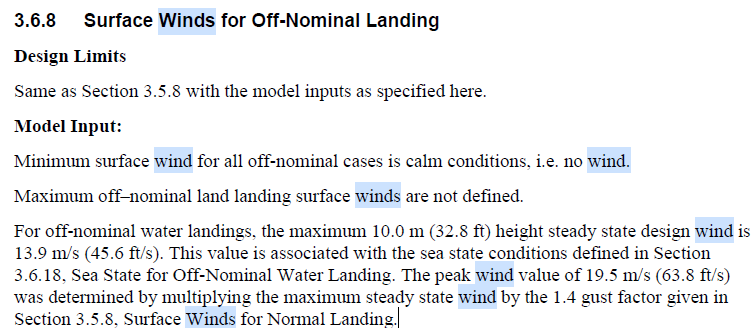

Then when I tried this the graphs were large. So I did v = 2m/s instead for wind(default setting for open rocket)

windVelMax = 13.91 % in m/s

Note that it is pulled from onshape inspection. Unfortunately, onshape does not allow for the output of a mass vs. x-position table

% Recall that cosine gust velocity profile is stored here: vg
% From the U.S Standard Atmosphere (1976) at the altitude of Max Q (1114.7
% m) . Air Density = 1.09917 kg/m^3

momentOfInertia2BArc = 5.2636

% 
rhoMaxQ = 1.09917

vehicleVelTimeGustCOS = table2array(vehicleVelTimeGustCOS)
vehicleWindTimeGustCOS = table2array(vehicleWindTimeGustCOS)
% velocity for dynamic array
velRel = vehicleVelTimeGustCOS(:,2) - vehicleWindTimeGustCOS(:,2)

% Lift Nosecone
Nnosecone = (9/2).*(rhoMaxQ.*velRel.*bodyTubeArea).*(noseCna)

% Lift of ALL 3 fins
Nfins = (9/2).*(rhoMaxQ.*velRel.*bodyTubeArea).*(finsCna)

% Lift of the Boat Tail
Nbt = 0 % 0 since there are no plans for boat-tail. additionally, no boat tail is good for a conservative estimate.


part1OfREqn =     5.1878
    5.1886
    5.1895
    5.1903
    5.1912
    5.1920
    5.1929
    5.1937
    5.1946
    5.1955
    5.1963
    5.1972
    5.1980
    5.1989
    5.1997


## Shear Force: a_y sum(m)


$$V_s(@x_k) = L_{nose}+L_{fins}-L_{boat-tail}-a_y \sum_{i=1}^{x_k}m-R\sum_{i=1}^{x_k}m(x_{cg}-x_m)$$


$d $ = fuselage diameter d

$R$ = Static Margin

**In the interest of data analysis time, the lateral  acceleration is used exactly at the time of max Q.** This lateral  acceleration is applied acorss the board as an array the size of the 'gust velocity profile' array. In the next iteration, we will want to properly extract all of the vertical acceleration values, as they change over the duration of the gust

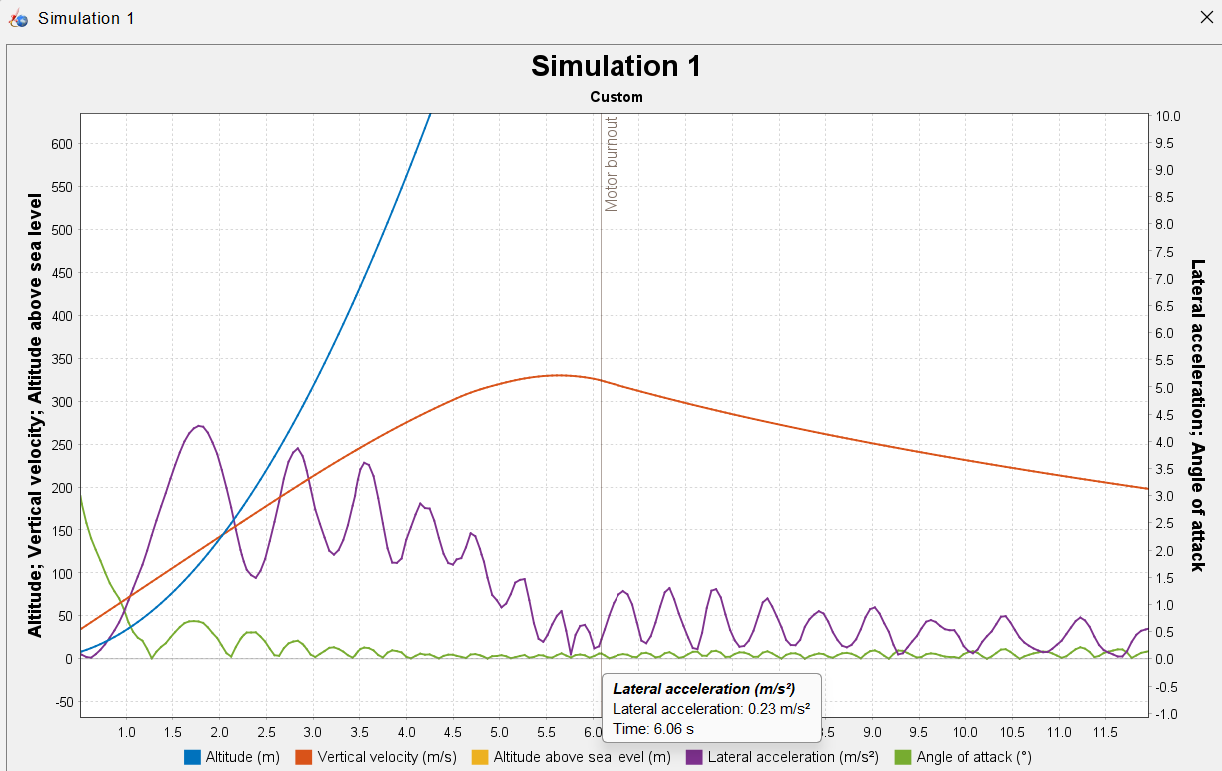

% 0.23 m/s^2 comes from the graph above
% t
% M_before

L1 = 1.0283

NlatAccel = vehicleLAccTimeGustCOS(:,2).*M_before

L2 = 1.5682

L3 = 1.9667

## Shear Force: Static Margin

In this problem(to save time) we use the 'uniform cylinder approximation for the moment of inertia in the lateral axis. Note that the center of gravity is not centered on the longitude of the rocket, so it would idealy be calculated with the parallel axis theorem: 


$$I = \sum{(I_{component,own} + mr^2)}$$


But for speed and simplicity we use the uniform cylinder approximation:


$$I = \frac{1}{12}m(3r^3+L^2)$$


where r is the fuselage radius, and L is the length of the cylinder, and m is the mass.

Pulling those values from the onshape document below:

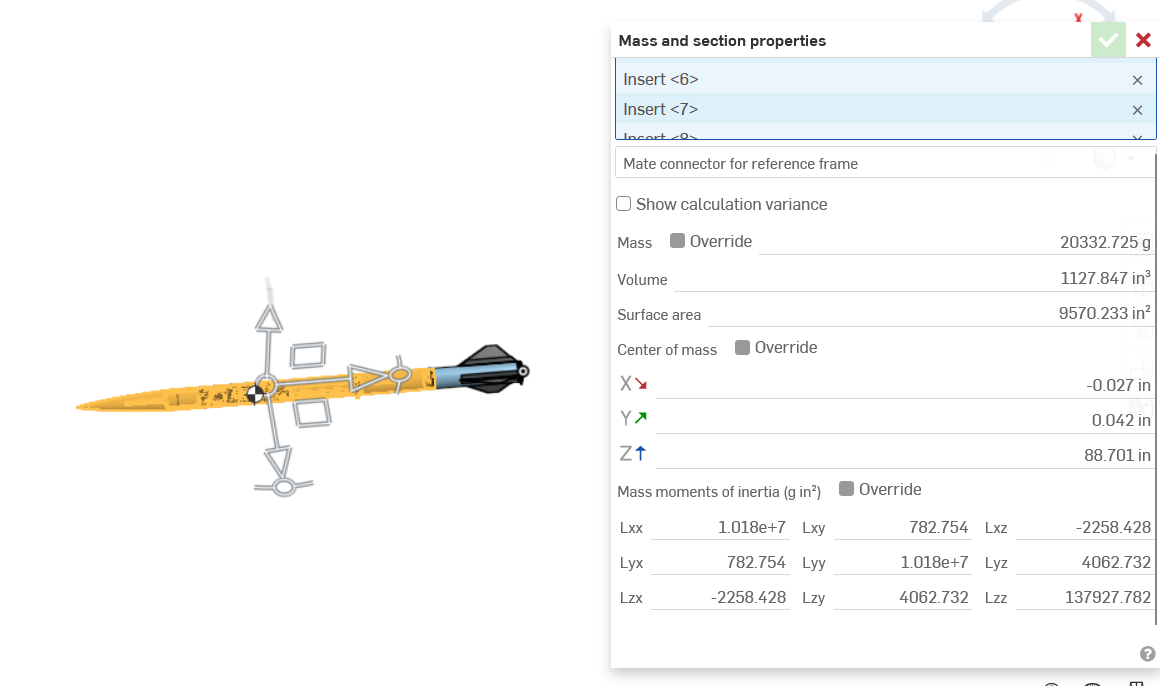

**Using the information given from OnShape makes a simplifying assumption that bypasses individual component **$I
$**, and assumes a uniform, perfrect cylinder from the tip of the nose cone to the back arc clamps. This makes for a conservative estimate for lift by increasing moment of inertia**

Mass = 20.332725 kg

Length = 1.762 meters

r = 0.169 meters /2 = 0.0845 meters

mass2Arc = 20.332725;

staticMargin = -1.9695

lengthNose2Arc = 1.762;
fuselageR = dBodyTube/2;

shearFrStaticMargin =   -10.2174
  -10.2190
  -10.2207
  -10.2224
  -10.2241
  -10.2258
  -10.2274
  -10.2291
  -10.2308
  -10.2325
  -10.2342
  -10.2359
  -10.2375
  -10.2392
  -10.2409


momentOfInertia2BArc = (1/12)*(mass2Arc)*(3*fuselageR^3 + lengthNose2Arc^2)


$$V_s(@x_k) = L_{nose}+L_{fins}-L_{boat-tail}-a_y \sum_{i=1}^{x_k}m-R\sum_{i=1}^{x_k}m(x_{cg}-x_m)$$


$d $ = fuselage diameter d

$R$ = Angular Acceleration

If you have the L1, L2, and L3 are gien in meters(rather than calibres)


$$R = \frac{9}{2I} \rho V (static-margin) $$


Static Margin is this:

L1, L2 and L3 are the moment arms of the nose, fins, and boat-tail from their respective centres of pressure to the C.G.

For speed, I used the values for the moment arms as shown in the spreadsheet below:

[https://docs.google.com/spreadsheets/d/1YpCOBGyIhGbyl9DqY5GLDXi1CcHhjao9K5FwuqBK1_Q/edit?usp=sharing](https://docs.google.com/spreadsheets/d/1YpCOBGyIhGbyl9DqY5GLDXi1CcHhjao9K5FwuqBK1_Q/edit?usp=sharing)

part1OfREqn = (9/(2*momentOfInertia2BArc))*(rhoMaxQ*gustArray(:,1))

NlatAccel =    37.2229
   36.8673
   36.5118
   36.1562
   35.8007
   35.4451
   35.0896
   34.7340
   34.3785
   34.0229
   33.6674
   33.3118
   32.9563
   32.6007
   32.2452



% from the spreadsheet above (in meters):
L1 = 1.028330124

totalShearFnOfGustVel =    48.1568
   48.5147
   48.8727
   49.2306
   49.5886
   49.9465
   50.3045
   50.6624
   51.0204
   51.3783
   51.7363
   52.0942
   52.4522
   52.8101
   53.1681


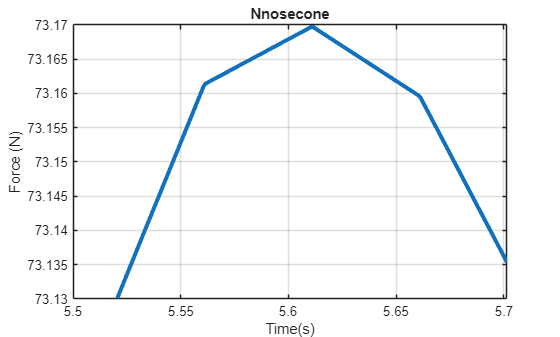

L2 = 1.568169876
L3 = 1.966669876


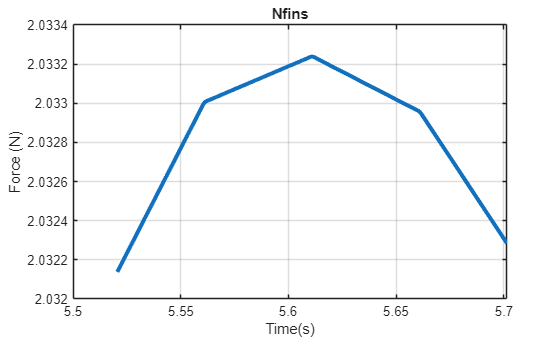

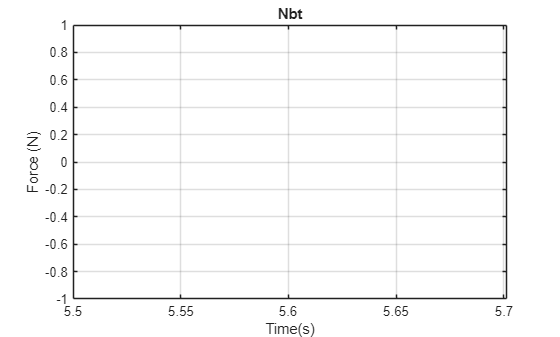

staticMargin = ((-1)*noseCna*L1 + finsCna*L2 + (-1)*boattailCna*L3)

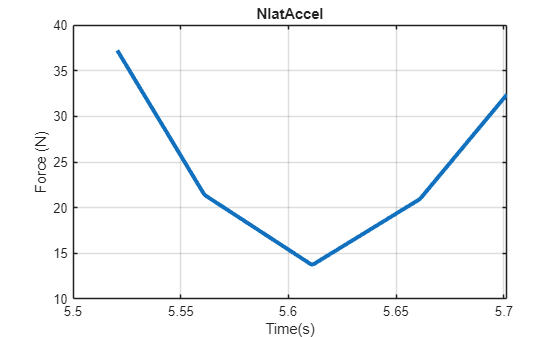

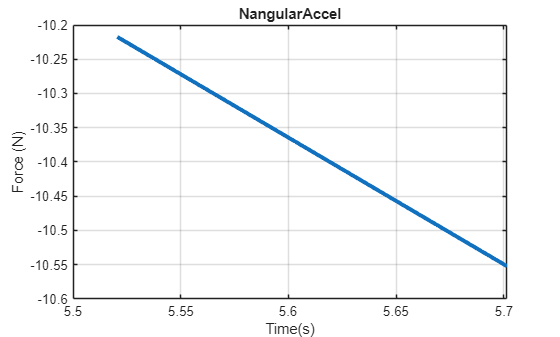

shearFrStaticMargin = part1OfREqn*staticMargin

## Shear Force: Stability Components, Vertical Acceleration, and Static Margin

Bringing all of the shear force component from above together;

% due to preious errors, turning the things into arrays
NlatAccel = table2array(NlatAccel)
% Nfins = table2array(Nfins)
% Nnosecone = table2array(Nnosecone)
totalShearFnOfGustVel = Nnosecone + Nfins - Nbt - NlatAccel - shearFrStaticMargin


Stick the shear force on the back arc clamps on a graph related to time:

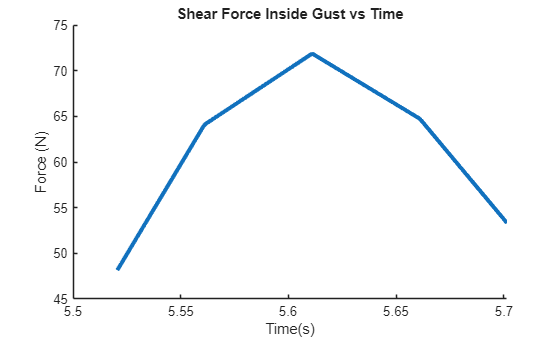

figure; plot(gustArray(:,1), Nnosecone, 'LineWidth', 3); xlabel('Time(s)'); ylabel('Force (N)'); title('Nnosecone'); grid on

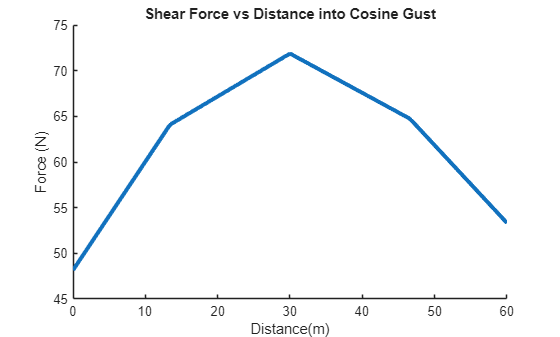

figure; plot(gustArray(:,1), Nfins, 'LineWidth', 3);  xlabel('Time(s)'); ylabel('Force (N)');   title('Nfins');     grid on
figure; plot(gustArray(:,1), Nbt, 'LineWidth', 3);  xlabel('Time(s)'); ylabel('Force (N)');     title('Nbt');       grid on
figure; plot(gustArray(:,1), NlatAccel, 'LineWidth', 3); xlabel('Time(s)'); ylabel('Force (N)');title('NlatAccel');grid on
figure; plot(gustArray(:,1), shearFrStaticMargin, 'LineWidth', 3); xlabel('Time(s)'); ylabel('Force (N)'); title('NangularAccel'); grid on

% figure; plot(gustArray(:,1), gust.aoa_array); title('Angle of Attack'); grid on



% Shear Force vs. Time
figure;

Max Shear is (N) : 71.809829

hold on;
title('Shear Force Inside Gust vs Time')
xlabel('Time(s)')
ylabel('Force (N)')

plot(gustArray(:,1), totalShearFnOfGustVel(:,1), 'LineWidth', 3);

% Shear Force vs. Distance
figure;
hold on;
title('Shear Force vs Distance into Cosine Gust')
xlabel('Distance(m)')
ylabel('Force (N)')
plot(gustArray(:,3), (totalShearFnOfGustVel(:,1)), 'LineWidth', 3);

fprintf('Max Shear is (N) : %f%', max(totalShearFnOfGustVel(:,1)))

save('shearDGustProfile.mat', 'totalShearFnOfGustVel')
save('shearDGustTimeDist.mat', 'gustArray')



## Shear Force: Including Points Outside of the Gust

## Shear Force: Vertical Acceleration at Points of Interest

Recall that we are looking at the forces on the ERS, as well as the arc clamps. 

**Arc Clamps**

For the Arc Clamps, we know from the CFD that the largest shear at max Q is at around 3.40 meters. 

[https://docs.google.com/spreadsheets/d/1YpCOBGyIhGbyl9DqY5GLDXi1CcHhjao9K5FwuqBK1_Q/edit?usp=sharing](https://docs.google.com/spreadsheets/d/1YpCOBGyIhGbyl9DqY5GLDXi1CcHhjao9K5FwuqBK1_Q/edit?usp=sharing)

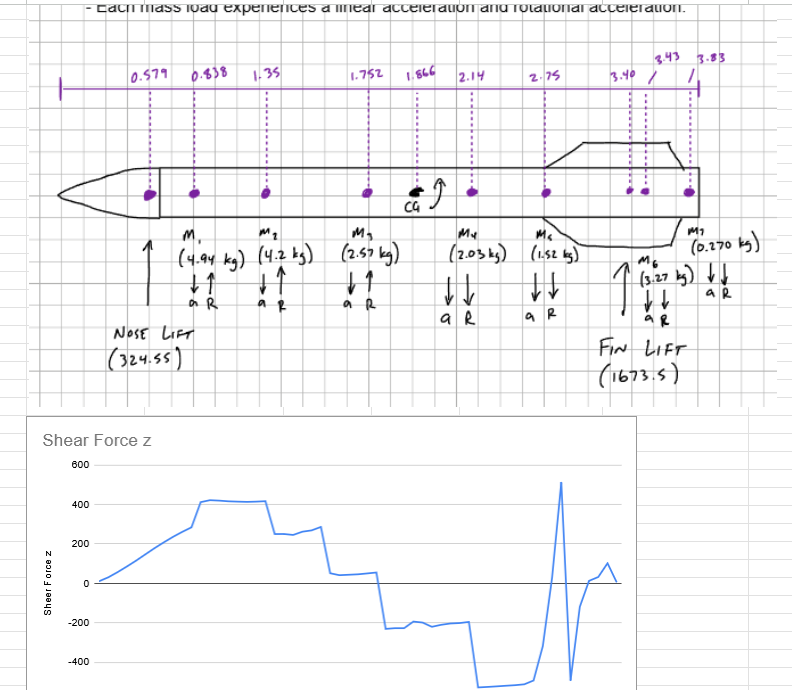

Closest arc clamps to this max shear force point is shown below:

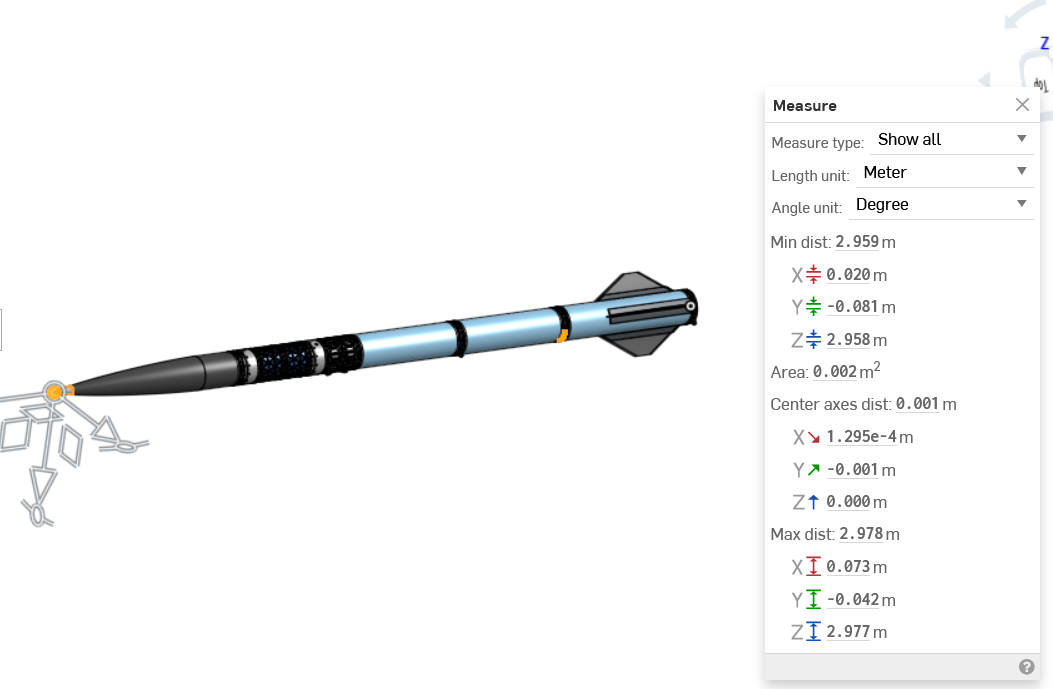

## Arc Clamps that Receive the Most Force


%yep placeholder


## Bending Moments


$$M_B(@x_k) = L_{nose}(x_k-x_{nose})+L_{boat}(x_k-x_{boat})+L_{fin}(x_k-x_{fin})-a_y\sum_{0}^{x_k}(x_k-x_m)-R\sum_{0}^{x_k}m(x_k-x_m)(x_{CG}-x_m)}$$


where$x_m
$ is the position of each individual mass of the individual components

## Bending Moments: Pulling Data for the x's

%% =========================================================
%  OpenRocket Component Position + Moment Extractor
% ==========================================================

clear; clc;

%% LOAD FILE
fn = "rocketComponentValuesOR.csv";
T = readtable(fn,"TextType","string","VariableNamingRule","preserve");

vars = string(T.Properties.VariableNames);

disp("Detected columns:")

Detected columns:


disp(vars')

    "Component"
    "Instance Mass (g)"
    "Aggregate Mass (g)"
    "Aggregate CG Location (cm)"
    "CP (cm)"
    "Normal Force Coefficient"




%% ----------------------------------------------------------
% FIND NAME COLUMN
%% ----------------------------------------------------------
nameCol = vars(contains(lower(vars),"component") | contains(lower(vars),"name"));
if isempty(nameCol)
    error("No component/name column found.");
end
nameCol = nameCol(1);
names = T.(nameCol);

%% ----------------------------------------------------------
% FIND MASS COLUMN
%% ----------------------------------------------------------
massCol = vars(contains(lower(vars),"mass"));
if isempty(massCol)
    error("No mass column found.");
end
massCol = massCol(1);
m = T.(massCol);

%% ----------------------------------------------------------
% FIND CG COLUMN (xm)
%% ----------------------------------------------------------
cgCol = vars(contains(lower(vars),"cg") & contains(lower(vars),"location"));
if isempty(cgCol)
    error("No CG location column found.");
end
cgCol = cgCol(1);
xm = T.(cgCol);

%% ----------------------------------------------------------
% REMOVE TOTAL ROW
%% ----------------------------------------------------------
valid = ~contains(lower(names),"total");

names = names(valid);
xm    = xm(valid);
m     = m(valid);

%% ----------------------------------------------------------
% USER INPUT: STATION LOCATION x
%% ----------------------------------------------------------
x = 230;      % <-- CHANGE THIS VALUE (cm from nose)

%% ----------------------------------------------------------
% CALCULATIONS
%% ----------------------------------------------------------
dx = xm - x;             % (xm − x)
momentTerm = m .* dx;    % m(xm − x)

%% ----------------------------------------------------------
% FULL TABLE (ALL COMPONENTS)
%% ----------------------------------------------------------
fullTable = table(names, m, xm, dx, momentTerm, ...
    'VariableNames', ["Component","Mass_g","xm_cm","xm_minus_x_cm","m_dx"]);

% sort by absolute distance from x
[~,idx] = sort(abs(dx));
fullTable = fullTable(idx,:);

disp(" ")

disp("===== ALL COMPONENTS =====")

===== ALL COMPONENTS =====


disp(fullTable)

                                Component                                 Mass_g    xm_cm     xm_minus_x_cm       m_dx    
    __________________________________________________________________    ______    ______    _____________    ___________

    "arc clamp system"                                                    97.567    225.21       -4.7909           -467.43
    "arc clamp system"                                                      97.6    240.93        10.931            1066.9
    "nuts & washer"                                                       45.359    242.18        12.181            552.53
    "Bulkhead"                                                             141.1    242.36        12.365            1744.7
    "Avionics Module (Third)"                                             2031.2    214.78 


%% ----------------------------------------------------------
% IMPORTANT COMPONENT FILTER
%% ----------------------------------------------------------
importantKeywords = [
    "nose"
    "fin"
    "motor"
    "engine"
    "payload"
    "avionics"
    "recovery"
    "parachute"
    "tube"
    "arc rings"
];

importantMask = false(size(names));

for k = 1:length(importantKeywords)
    importantMask = importantMask | contains(lower(names),importantKeywords(k));
end

importantTable = fullTable(importantMask(idx),:);

disp(" ")

disp("===== IMPORTANT COMPONENTS ONLY =====")

===== IMPORTANT COMPONENTS ONLY =====


disp(importantTable)

                        Component                         Mass_g    xm_cm     xm_minus_x_cm       m_dx    
    __________________________________________________    ______    ______    _____________    ___________

    "Avionics Module (Third)"                             2031.2    214.78       -15.217            -30908
    "avionics guts wooden frame and 3d printed spacer"     226.8     210.5       -19.498             -4422
    "Main Parachute"                                        1111    134.43       -95.571       -1.0618e+05
    "Trapezoidal fin module"                              1147.2    326.18        96.179        1.1034e+05
    "Fin Can Module"                                      3764.4     348.2         118.2        4.4496e+05
    "ERS Micromodule Attached to Nose Cone"               2048.4     109.6      


%% ----------------------------------------------------------
% TOTAL SUMS (for bending equation use)
%% ----------------------------------------------------------
totalMoment = sum(momentTerm);
disp(" ")

disp("Total Σ m(xm − x) = " + totalMoment + " g·cm")

Total Σ m(xm − x) = -248890.4398 g·cm


## Bending Moments: Math for Bending Using Component x-pos

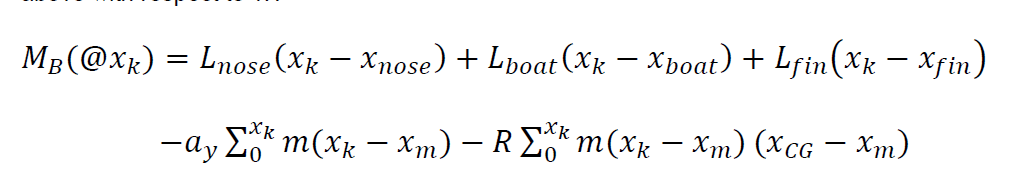

% x_m - x position(in meters) of the arc clamps in the very back (in m)
% x_m - 


% deltXNose  = -1*importantTable(8,4)/100 % in meters, w/ conversion factor cm -> m, 
%         % and then multiplied by -1 to get x_cm - xm
% deltXboat; % currently this is undefined as the boattail is not attached
% deltXfin = -1*importantTable(5,4)/100 % in meters, w/ conversion factor



From the table outputted above, as of 2/18/26's revision, the corresponding row with the component that contains these delta x's 

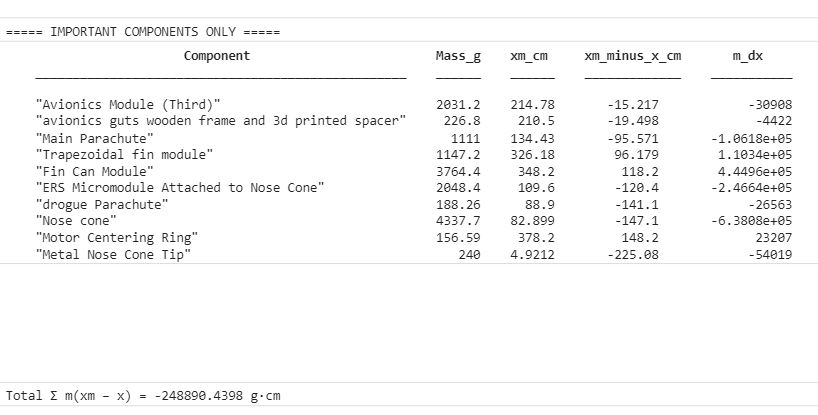


% Mbending_backArcClamp = Nnosecone*() + Nbt*(x_m -) +  Nfins*(x_m -) - ay 

## Continuous Gust Profile

From Aspire Space Paper:

"The vehicle accelerates in the direction of the total lift which builds up a lateral airspeed component that reduces the angle of attack. Simultaneously the fins rotate the vehicle to reduce the angle of attack further in a highly damped oscillatory motion."

So looking at the laterial continuous gust profile from Kopasakis(2010) "Atmospheric Turbulence Modeling for Aero Vehicles: Fractional Order Fits"

We assume Umax = 2sigma as a conservative estimate 

Getting the table values, picked the one at 5km since it is more conservative of a dvisc. from (Tables of the U.S. Standard Atmosphere, 1976)

:

[https://www.pdas.com/bigtables.html](https://www.pdas.com/bigtables.html)

% kinematic viscocity
dvisc = 2.2110E-05;

% l aka atmospheric region of size l
% use the same l(dm*2) from the discrete gust simulation above
% l = (dmMQ*2);


% vprime aka velocity fluctuation in atmospheric region side l.
% note that vprime =~u' 
% assume 2sigma = Umax
% sigma = Umax/2 = vprime = 
% note that from the discrete gust, vm = Umax
vprime = (vm/2)

Unrecognized function or variable 'vm'.




% eddy dissipation aka epsilon stuff
epsilon = (dvisc*vprime^2)/(l^2)

s = tf('s');

% traverse acoustic wave velocity
GVA = ( (56*epsilon^(2/9))*((s/9.2+1)*(s/55.0+1)*(s/335.5+1)) )/( (s/1.46+1)*(s/30.1+1)*(s/85.7+1)* (s/1593.1+1) )

step(GVA)